clear;
clc;

% Lapso temporal
t = linspace(0, 3e4, 1e6);

% Constantes (SSO)
mu = 3.986004418e14;
J3 = - 2.532435346e-6;
R = 6378.137e3;
a = 7211.54e3;
e = 0.01;
n = sqrt(mu / a^3);
INC     = deg2rad(98.7);
omega   = deg2rad(30);
theta_0 = deg2rad(0);

% Condiciones iniciales
x0  = 0;
y0  = 0;
z0  = 0;
dx0 = 0;
dy0 = 0;
dz0 = 0;

eta     = n*t/2;
alpha1  =     omega +   theta_0;
alpha2  =   2*omega +   theta_0;
alpha3  =   2*omega + 3*theta_0;
alpha4  =     omega + 2*theta_0;
alpha5  =     omega + 3*theta_0;
alpha6  =     omega -   theta_0;
alpha7  =   3*omega +   theta_0;
alpha8  =   3*omega + 2*theta_0;
alpha9  =   3*omega + 4*theta_0;
alpha10 =   3*omega + 5*theta_0;
alpha11 =     omega + 3*theta_0;
alpha12 =     omega + 4*theta_0;
alpha13 =     omega - 2*theta_0;


beta1   =       eta +    alpha1;
beta2   =     3*eta +  2*alpha1;
beta3   =       eta +  2*alpha1;
beta4   =       eta -  2*alpha1;
beta5   =     2*eta +    alpha1;
beta6   =     3*eta +    alpha1;
beta7   =     4*eta +    alpha1;
beta8   =    -  eta +    alpha1;
beta9   =   - 2*eta +    alpha1;

beta10  =     2*eta +    alpha2;
beta11  =     4*eta +    alpha2;
beta12  =   - 2*eta +    alpha2;

beta13  =    4*eta +    alpha3;
beta14  =    6*eta +    alpha3;
beta15  =  - 2*eta +    alpha3;

beta16  =      eta +    alpha4;
beta17  =    2*eta +    alpha4;
beta18  =    3*eta +    alpha4;
beta19  =    4*eta +    alpha4;
beta20  =    - eta +    alpha4;
beta21  =  - 2*eta +    alpha4;

beta22  =     2*eta +    alpha5;
beta23  =     4*eta +    alpha5;
beta24  =     6*eta +    alpha5;
beta25  =   - 2*eta +    alpha5;

beta26  =     2*eta +    alpha6;
beta27  =   - 2*eta +    alpha6;


beta28  =     2*eta +  3*alpha1;
beta29  =     4*eta +  3*alpha1;
beta30  =     6*eta +  3*alpha1;
beta31  =     8*eta +  3*alpha1;
beta32  =   - 2*eta +  3*alpha1;

beta33  =     8*eta +    alpha2;
beta34  =     2*eta +    alpha3;

beta35  =     8*eta +    alpha3;
 
beta36  =     6*eta +    alpha4;
beta37  =     2*eta +  3*alpha4;
beta38  =     8*eta +  3*alpha4;
beta39  =    10*eta +  3*alpha4;
beta40  =   - 2*eta +  3*alpha4;
 
beta41  =     2*eta +    alpha7;
beta42  =     4*eta +    alpha7;
beta43  =     6*eta +    alpha7;
beta44  =   - 2*eta +    alpha7;
 
beta45  =     2*eta +   alpha12;
beta46  =     4*eta +   alpha12;
beta47  =     6*eta +   alpha12;
beta48  =   - 2*eta +   alpha12;
 
beta49  =     2*eta +    alpha8;
beta50  =     4*eta +    alpha8;
beta51  =     6*eta +    alpha8;
beta52  =     8*eta +    alpha8;
beta53  =   - 2*eta +    alpha8;
 
beta54  =     2*eta +    alpha9;
beta55  =     4*eta +    alpha9;
beta56  =     6*eta +    alpha9;
beta57  =     8*eta +    alpha9;
beta58  =    10*eta +    alpha9;
beta59  =   - 2*eta +    alpha9;
 
beta60  =     2*eta +   alpha10;
beta61  =     6*eta +   alpha10;
beta62  =     8*eta +   alpha10;
beta63  =    10*eta +   alpha10;
beta64  =   - 2*eta +   alpha10;
 
beta65  =     2*eta +   alpha11;
beta66  =     4*eta +   alpha11;
beta67  =     6*eta +   alpha11;
beta68  =   - 2*eta +   alpha11;
     
beta69  =     2*eta +   alpha13;
beta70  =   - 2*eta +   alpha13;


tau1    =     2*eta +   theta_0;
tau2    =   - 2*eta +   theta_0;
o1      =       eta +     omega;
o2      =     2*eta +     omega;
o3      =     - eta +     omega;
o4      =   - 2*eta +     omega;
o5      =     4*eta +     omega;
o6      =     2*eta +   3*omega;
o7      =     4*eta +   3*omega;
o8      =   - 2*eta +   3*omega;
zeta_i  = sin(INC) + 5*sin(3*INC);
zeta_a1 = sin(alpha1) + 5*sin(3*alpha1);
Zeta_i  = 5*sin(INC)^2 - 4;

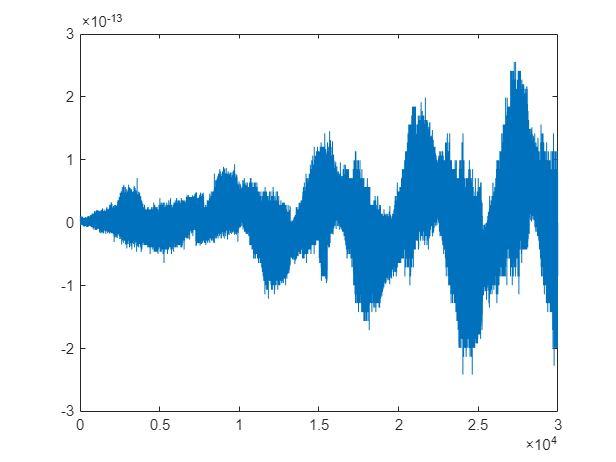

% Solución analítica
xJ3B = (-(1536.*a.^2.*n - 1152.*a.^2.*n.*cos(n.*t) - 7680.*a.^2.*e.^2.*n + 15360.*a.^2.*e.^4.*n - 15360.*a.^2.*e.^6.*n + 7680.*a.^2.*e.^8.*n - 1536.*a.^2.*e.^10.*n + 5760.*a.^2.*e.^2.*n.*cos(n.*t) - 11520.*a.^2.*e.^4.*n.*cos(n.*t) + 11520.*a.^2.*e.^6.*n.*cos(n.*t) - 5760.*a.^2.*e.^8.*n.*cos(n.*t) + 1152.*a.^2.*e.^10.*n.*cos(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*x0 + (-(384.*sin(n.*t).*a.^2 - 1920.*sin(n.*t).*a.^2.*e.^2 + 3840.*sin(n.*t).*a.^2.*e.^4 - 3840.*sin(n.*t).*a.^2.*e.^6 + 1920.*sin(n.*t).*a.^2.*e.^8 - 384.*sin(n.*t).*a.^2.*e.^10)./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*dx0 + (-(768.*a.^2 - 768.*a.^2.*cos(n.*t) - 3840.*a.^2.*e.^2 + 7680.*a.^2.*e.^4 - 7680.*a.^2.*e.^6 + 3840.*a.^2.*e.^8 - 768.*a.^2.*e.^10 + 3840.*a.^2.*e.^2.*cos(n.*t) - 7680.*a.^2.*e.^4.*cos(n.*t) + 7680.*a.^2.*e.^6.*cos(n.*t) - 3840.*a.^2.*e.^8.*cos(n.*t) + 768.*a.^2.*e.^10.*cos(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*dy0 + ((1800.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(INC) - 120.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega) - 5400.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(omega) - 120.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0) + 360.*R.^3.*n.*sin(3.*INC).*cos(omega).*sin(theta_0) + 360.*R.^3.*n.*sin(3.*INC).*cos(theta_0).*sin(omega) + 108.*R.^3.*e.*n.*sin(INC).*sin(omega) - 600.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega) + 360.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(INC) + 360.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(INC) + 540.*R.^3.*e.*n.*sin(3.*INC).*sin(omega) + 16200.*R.^3.*e.^3.*n.*sin(INC).*sin(omega) + 72.*R.^3.*n.*sin(INC).*cos(omega).*sin(theta_0) + 72.*R.^3.*n.*sin(INC).*cos(theta_0).*sin(omega) + 720.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(omega) + 720.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(omega) + 360.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(INC) + 360.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(INC) + 630.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(INC) + 630.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(INC) - 4530.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(omega).*sin(theta_0) - 4410.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(theta_0).*sin(omega) - 630.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(INC).*sin(theta_0) - 810.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(INC).*sin(omega) - 630.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(INC).*cos(theta_0) - 810.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(INC).*cos(omega) + 14400.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(INC).*sin(omega) + 28800.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(INC).*cos(omega) - 1800.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(INC).*sin(omega) - 1800.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(INC).*cos(omega) - 180.*R.^3.*n.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 108.*R.^3.*e.*n.*cos(n.*t).*sin(INC).*sin(omega) + 54.*R.^3.*e.*n.*sin(n.*t).*sin(INC).*cos(omega) + 475.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(n.*t) + 725.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*cos(n.*t) - 200.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*n.*t) - 200.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*cos(2.*n.*t) + 75.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*n.*t) + 75.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*cos(3.*n.*t) + 72.*R.^3.*e.*n.^2.*t.*sin(INC).*cos(omega) + 135.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t).*sin(INC) - 315.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) - 315.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 45.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 45.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC) - 45.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 120.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0) - 120.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega) - 210.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0) - 210.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega) + 210.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(theta_0) - 210.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(omega) + 210.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(theta_0) - 210.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(omega) - 1665.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(INC) - 1665.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(INC) - 4800.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(omega) - 9600.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(omega) + 2700.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(INC) + 2700.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(INC) - 603.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*sin(INC) - 603.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*sin(INC) + 600.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(omega) + 600.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(omega) + 1080.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(INC) + 1080.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(INC) + 180.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*sin(INC) + 180.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*sin(INC) - 135.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) + 45.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 540.*R.^3.*e.*n.*sin(3.*INC).*cos(n.*t).*sin(omega) + 270.*R.^3.*e.*n.*sin(3.*INC).*sin(n.*t).*cos(omega) - 12000.*R.^3.*e.^3.*n.*cos(n.*t).*sin(INC).*sin(omega) - 4200.*R.^3.*e.^3.*n.*sin(n.*t).*sin(INC).*cos(omega) - 4200.*R.^3.*e.^3.*n.*cos(2.*n.*t).*sin(INC).*sin(omega) - 4200.*R.^3.*e.^3.*n.*sin(2.*n.*t).*sin(INC).*cos(omega) - 72.*R.^3.*n.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 72.*R.^3.*n.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 36.*R.^3.*n.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 360.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(omega) - 45.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t) + 105.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t) + 105.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t) + 15.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t) + 15.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t) + 15.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 144.*R.^3.*e.*n.*cos(2.*theta_0).*sin(INC).*sin(omega) + 144.*R.^3.*e.*n.*sin(2.*theta_0).*sin(INC).*cos(omega) + 12150.*R.^3.*e.^2.*n.*sin(INC).*cos(omega).*sin(theta_0) + 6030.*R.^3.*e.^2.*n.*sin(INC).*cos(theta_0).*sin(omega) - 36.*R.^3.*n.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 555.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0) + 555.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega) - 900.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0) - 900.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega) + 201.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0) + 201.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega) - 360.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0) - 360.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega) - 60.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0) - 60.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega) + 45.*R.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t) - 15.*R.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t) + 4000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(n.*t).*sin(omega) + 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(n.*t).*cos(omega) - 1425.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(n.*t).*sin(INC) - 2175.*R.^3.*e.^3.*n.*sin(3.*omega).*cos(n.*t).*sin(INC) + 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*n.*t).*sin(omega) + 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*n.*t).*cos(omega) + 600.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*n.*t).*sin(INC) + 600.*R.^3.*e.^3.*n.*sin(3.*omega).*cos(2.*n.*t).*sin(INC) - 225.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(3.*n.*t).*sin(INC) - 225.*R.^3.*e.^3.*n.*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 360.*R.^3.*n.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 360.*R.^3.*n.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 180.*R.^3.*n.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*cos(n.*t) + 126.*R.^3.*e.*n.^2.*t.*sin(n.*t).*sin(INC).*sin(omega) - (255.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t))./2 + (195.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t))./2 + (195.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t))./2 - 60.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - (195.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t))./2 - 60.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + (375.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t))./2 - 60.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(2.*n.*t) + (375.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t))./2 + (165.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t))./2 + (165.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t))./2 + (165.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t))./2 - (15.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t))./2 - (15.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t))./2 - (15.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t))./2 + 30.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(4.*n.*t) + 30.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + 30.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(4.*n.*t) - (245.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*sin(theta_0))./2 + (305.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*cos(theta_0))./2 + 1130.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 700.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) - (245.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*cos(theta_0))./2 + 1130.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 120.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t).*sin(INC) + 1440.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) + 1440.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + 4575.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 2025.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 9375.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) - 1725.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t).*sin(INC) - 3075.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 3075.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 230.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*n.*t).*sin(theta_0) - 230.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*n.*t).*cos(theta_0) - 1010.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 1010.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 230.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(2.*n.*t).*cos(theta_0) - 1010.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 210.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(2.*n.*t).*sin(INC) - (225.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(n.*t).*sin(INC))./2 + 210.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC) + (1005.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(n.*t).*sin(INC))./2 + 210.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(2.*n.*t).*sin(INC) + (1005.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC))./2 + 575.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*sin(omega) + 625.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*cos(omega) + 575.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*cos(omega) - 300.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t).*sin(INC) - 1050.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC) - 1050.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + (285.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*n.*t).*sin(theta_0))./2 + (285.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*n.*t).*cos(theta_0))./2 + 90.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 90.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) + (285.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(3.*n.*t).*cos(theta_0))./2 + 90.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) + 360.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC) + 360.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC) + 360.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(3.*n.*t).*sin(omega) + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*n.*t).*cos(omega) + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(3.*n.*t).*cos(omega) + 675.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 345.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(4.*n.*t).*sin(INC) - 345.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t).*sin(INC) - 345.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) - 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(2.*n.*t).*sin(omega) - 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(2.*n.*t).*cos(omega) - 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(2.*n.*t).*cos(omega) - 300.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(4.*n.*t).*sin(INC) - 600.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(2.*n.*t).*sin(INC) - 300.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t).*sin(INC) - 600.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC) - 150.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(n.*t).*sin(INC) - 300.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) - 600.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(2.*n.*t).*sin(INC) - 150.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + (495.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(3.*n.*t).*sin(INC))./2 + (495.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t).*sin(INC))./2 + (495.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC))./2 + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(3.*n.*t).*sin(omega) + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*n.*t).*cos(omega) + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(3.*n.*t).*cos(omega) + 675.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 105.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(4.*n.*t).*sin(INC) - 105.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t).*sin(INC) - 105.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) - 42.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(5.*n.*t).*sin(INC) - 42.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t).*sin(INC) - 42.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(5.*n.*t).*sin(INC) - 105.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(5.*n.*t).*sin(INC) - 225.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(3.*n.*t).*sin(INC) - 105.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t).*sin(INC) - 225.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t).*sin(INC) - 105.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(5.*n.*t).*sin(INC) - 225.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + 300.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(4.*n.*t).*sin(INC) + 300.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t).*sin(INC) + 300.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) - 105.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(5.*n.*t).*sin(INC) - 105.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t).*sin(INC) - 105.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(5.*n.*t).*sin(INC) + 300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*sin(n.*t) + (255.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t))./2 + 60.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + (195.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t))./2 - (165.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t))./2 + (15.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t))./2 - 30.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - (305.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*sin(theta_0))./2 - 700.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 120.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) - 12825.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 1725.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 230.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*n.*t).*sin(theta_0) + 1010.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 210.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC) + (225.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(n.*t).*sin(INC))./2 - 625.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*sin(omega) + 300.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC) - (285.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*n.*t).*sin(theta_0))./2 - 90.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) - 360.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(3.*n.*t).*sin(omega) - 675.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC) + 345.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t).*sin(INC) + 1400.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(2.*n.*t).*sin(omega) + 300.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t).*sin(INC) + 600.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC) - (495.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t).*sin(INC))./2 - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(3.*n.*t).*sin(omega) - 675.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC) + 105.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t).*sin(INC) + 42.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t).*sin(INC) + 105.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t).*sin(INC) + 225.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t).*sin(INC) - 300.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t).*sin(INC) + 105.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t).*sin(INC) - 630.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega) + 12600.*R.^3.*e.^3.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega) + 7200.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(omega) - 36.*R.^3.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 108.*R.^3.*e.*n.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 126.*R.^3.*e.*n.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 108.*R.^3.*e.*n.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 36.*R.^3.*e.*n.*cos(2.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) - 36.*R.^3.*e.*n.*cos(2.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) - 36.*R.^3.*e.*n.*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 10380.*R.^3.*e.^2.*n.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 4260.*R.^3.*e.^2.*n.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 1770.*R.^3.*e.^2.*n.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 1770.*R.^3.*e.^2.*n.*cos(2.*n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 1770.*R.^3.*e.^2.*n.*cos(2.*n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 1770.*R.^3.*e.^2.*n.*sin(2.*n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 630.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*sin(omega) - 14400.*R.^3.*e.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*sin(omega) + 40.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t) - 480.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t) - 480.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t) + 575.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t) + 1025.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t) + 1025.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t) - 70.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(2.*n.*t) + (75.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(n.*t))./2 - 70.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t) - (335.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(n.*t))./2 - 70.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(2.*n.*t) - (335.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(n.*t))./2 + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t) + 350.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t) + 350.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t) - 120.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t) - 120.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t) - 120.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t) - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t) - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t) - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 115.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(4.*n.*t) + 115.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t) + 115.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(4.*n.*t) + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(4.*n.*t) + 200.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(2.*n.*t) + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t) + 200.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t) + 50.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(n.*t) + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(4.*n.*t) + 200.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(2.*n.*t) + 50.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(n.*t) - (165.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(3.*n.*t))./2 - (165.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t))./2 - (165.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(3.*n.*t))./2 - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t) - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t) - 225.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 35.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(4.*n.*t) + 35.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t) + 35.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(4.*n.*t) + 14.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(5.*n.*t) + 14.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t) + 14.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(5.*n.*t) + 35.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(5.*n.*t) + 75.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*sin(3.*n.*t) + 35.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t) + 75.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t) + 35.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(5.*n.*t) + 75.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(3.*n.*t) - 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*sin(4.*n.*t) - 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t) - 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(4.*n.*t) + 35.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*sin(5.*n.*t) + 35.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t) + 35.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(5.*n.*t) + 360.*R.^3.*e.^2.*n.^2.*t.*sin(INC).*cos(omega).*cos(theta_0) + 36.*R.^3.*n.^2.*t.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 36.*R.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 36.*R.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 126.*R.^3.*e.*n.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 36.*R.^3.*e.*n.*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 14550.*R.^3.*e.^2.*n.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 1770.*R.^3.*e.^2.*n.*sin(2.*n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 40.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t) - 575.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t) + 70.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t) - (75.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(n.*t))./2 - 100.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t) + 120.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t) + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t) - 115.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t) - 100.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t) - 200.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t) + (165.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t))./2 + 225.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t) - 35.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t) - 14.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t) - 35.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t) - 75.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t) + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t) - 35.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t) - 8640.*R.^3.*e.^2.*n.^2.*t.*sin(INC).*sin(omega).*sin(theta_0) - 4200.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega) + 900.*R.^3.*e.^3.*n.^2.*t.*cos(3.*omega).*cos(n.*t).*sin(INC) - 180.*R.^3.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 540.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 630.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 540.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + (765.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t).*sin(INC))./2 - (585.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC))./2 - (585.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC))./2 - 180.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) - 180.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 180.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 180.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(2.*n.*t).*sin(INC) + (585.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t).*sin(INC))./2 + 180.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC) - (1125.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC))./2 + 180.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(2.*n.*t).*sin(INC) - (1125.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC))./2 - (495.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC))./2 - (495.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC))./2 - (495.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC))./2 + (45.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC))./2 + (45.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC))./2 + (45.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC))./2 - 90.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(4.*n.*t).*sin(INC) - 90.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*sin(INC) - 90.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) + 4420.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 4300.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 110.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + (735.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0))./2 - (915.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0))./2 - 510.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 660.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + (735.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0))./2 - 510.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 13725.*R.^3.*e.^3.*n.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 6075.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 28125.*R.^3.*e.^3.*n.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 110.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 110.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 110.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 690.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(2.*n.*t).*sin(INC).*sin(theta_0) + 690.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(2.*n.*t).*sin(INC).*cos(theta_0) + 1590.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) + 1590.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 690.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(2.*n.*t).*sin(INC).*cos(theta_0) + 1590.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 1725.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 1875.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 1725.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - (855.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*n.*t).*sin(INC).*sin(theta_0))./2 - (855.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*n.*t).*sin(INC).*cos(theta_0))./2 - 270.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) - 270.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) - (855.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(3.*n.*t).*sin(INC).*cos(theta_0))./2 - 270.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) - 675.*R.^3.*e.^3.*n.*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) - 675.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) - 675.*R.^3.*e.^3.*n.*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) + 4200.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) + 4200.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 4200.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 675.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) - 675.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) - 675.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) + 4800.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*sin(omega) - 900.*R.^3.*e.^3.*n.^2.*t.*sin(3.*omega).*sin(n.*t).*sin(INC) + 1800.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(omega).*cos(theta_0) + 180.*R.^3.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 180.*R.^3.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 180.*R.^3.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 630.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - (765.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC))./2 + 180.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) - 180.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC) - (585.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC))./2 + (495.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC))./2 - (45.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC))./2 + 90.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t).*sin(INC) - 5330.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + (915.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0))./2 + 660.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 38475.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 110.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0) - 690.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(2.*n.*t).*sin(INC).*sin(theta_0) - 1590.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 1875.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + (855.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*n.*t).*sin(INC).*sin(theta_0))./2 + 270.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) + 675.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) - 4200.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 675.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) - 126.*R.^3.*e.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega) + 2880.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(omega).*sin(theta_0) - 21600.*R.^3.*e.^3.*n.^2.*t.*sin(2.*theta_0).*sin(INC).*sin(omega) + 120.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*sin(theta_0) - 1050.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 120.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*sin(theta_0) + 120.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*cos(theta_0) - 1050.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) - 1050.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) + 3300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 6300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 5700.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) - 900.*R.^3.*e.^3.*n.^2.*t.*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) - 900.*R.^3.*e.^3.*n.^2.*t.*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) - 900.*R.^3.*e.^3.*n.^2.*t.*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 1500.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*sin(omega) - 1500.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*sin(omega) - 1500.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*cos(omega) - 54.*R.^3.*e.*n.^2.*t.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 4950.*R.^3.*e.^2.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t) + 54.*R.^3.*e.*n.^2.*t.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 54.*R.^3.*e.*n.^2.*t.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 54.*R.^3.*e.*n.^2.*t.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 9450.*R.^3.*e.^2.*n.^2.*t.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 8730.*R.^3.*e.^2.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 5670.*R.^3.*e.^2.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t) + 300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t) + 300.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t) - 270.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 2130.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 360.*R.^3.*e.^2.*n.^2.*t.*cos(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0) - 1710.*R.^3.*e.^2.*n.^2.*t.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 8100.*R.^3.*e.^3.*n.^2.*t.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 4500.*R.^3.*e.^3.*n.^2.*t.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 270.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 270.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 270.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 2670.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 2430.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 2370.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 360.*R.^3.*e.^2.*n.^2.*t.*cos(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0) + 1710.*R.^3.*e.^2.*n.^2.*t.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 360.*R.^3.*e.^2.*n.^2.*t.*sin(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0) - 360.*R.^3.*e.^2.*n.^2.*t.*sin(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0) + 1710.*R.^3.*e.^2.*n.^2.*t.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 1710.*R.^3.*e.^2.*n.^2.*t.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 9900.*R.^3.*e.^3.*n.^2.*t.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 18900.*R.^3.*e.^3.*n.^2.*t.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 17100.*R.^3.*e.^3.*n.^2.*t.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 4500.*R.^3.*e.^3.*n.^2.*t.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 4500.*R.^3.*e.^3.*n.^2.*t.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 4500.*R.^3.*e.^3.*n.^2.*t.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 120.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*cos(theta_0) + 1050.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) - 2700.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 900.*R.^3.*e.^3.*n.^2.*t.*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t).*sin(INC) + 1500.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*cos(omega))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*J3;
yJ3B = ((23040.*a.^2.*n.^2 - 115200.*a.^2.*e.^2.*n.^2 + 230400.*a.^2.*e.^4.*n.^2 - 230400.*a.^2.*e.^6.*n.^2 + 115200.*a.^2.*e.^8.*n.^2 - 23040.*a.^2.*e.^10.*n.^2)./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*x0.*t + (-(23040.*a.^2.*n.*sin(n.*t) - 115200.*a.^2.*e.^2.*n.*sin(n.*t) + 230400.*a.^2.*e.^4.*n.*sin(n.*t) - 230400.*a.^2.*e.^6.*n.*sin(n.*t) + 115200.*a.^2.*e.^8.*n.*sin(n.*t) - 23040.*a.^2.*e.^10.*n.*sin(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*x0 + (-(3840.*a.^2.*n - 19200.*a.^2.*e.^2.*n + 38400.*a.^2.*e.^4.*n - 38400.*a.^2.*e.^6.*n + 19200.*a.^2.*e.^8.*n - 3840.*a.^2.*e.^10.*n)./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*y0 + ((7680.*a.^2 - 7680.*a.^2.*cos(n.*t) - 38400.*a.^2.*e.^2 + 76800.*a.^2.*e.^4 - 76800.*a.^2.*e.^6 + 38400.*a.^2.*e.^8 - 7680.*a.^2.*e.^10 + 38400.*a.^2.*e.^2.*cos(n.*t) - 76800.*a.^2.*e.^4.*cos(n.*t) + 76800.*a.^2.*e.^6.*cos(n.*t) - 38400.*a.^2.*e.^8.*cos(n.*t) + 7680.*a.^2.*e.^10.*cos(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*dx0 + ((11520.*a.^2.*n - 57600.*a.^2.*e.^2.*n + 115200.*a.^2.*e.^4.*n - 115200.*a.^2.*e.^6.*n + 57600.*a.^2.*e.^8.*n - 11520.*a.^2.*e.^10.*n)./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*dy0.*t + (-(15360.*sin(n.*t).*a.^2 - 76800.*sin(n.*t).*a.^2.*e.^2 + 153600.*sin(n.*t).*a.^2.*e.^4 - 153600.*sin(n.*t).*a.^2.*e.^6 + 76800.*sin(n.*t).*a.^2.*e.^8 - 15360.*sin(n.*t).*a.^2.*e.^10)./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*dy0 + (-(2700.*R.^3.*e.*n.^3.*sin(3.*INC).*cos(omega) + 540.*R.^3.*e.*n.^3.*sin(INC).*cos(omega) + 2700.*R.^3.*e.^2.*n.^3.*sin(INC).*cos(omega).*cos(theta_0) - 64800.*R.^3.*e.^2.*n.^3.*sin(INC).*sin(omega).*sin(theta_0) + 13500.*R.^3.*e.^2.*n.^3.*sin(3.*INC).*cos(omega).*cos(theta_0) + 21600.*R.^3.*e.^2.*n.^3.*sin(3.*INC).*sin(omega).*sin(theta_0) - 162000.*R.^3.*e.^3.*n.^3.*sin(2.*theta_0).*sin(INC).*sin(omega) + 54000.*R.^3.*e.^3.*n.^3.*sin(3.*INC).*sin(2.*theta_0).*sin(omega))./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*t.^2.*J3 + ((9000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega) - 5400.*R.^3.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(INC) - 5400.*R.^3.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(INC) - 4500.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(omega) - 243000.*R.^3.*e.^3.*n.^2.*sin(INC).*sin(omega) - 1080.*R.^3.*n.^2.*sin(INC).*cos(omega).*sin(theta_0) - 1080.*R.^3.*n.^2.*sin(INC).*cos(theta_0).*sin(omega) + 1800.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0) + 1800.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega) + 81000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(omega) - 27000.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(INC) - 5400.*R.^3.*n.^2.*sin(3.*INC).*cos(omega).*sin(theta_0) - 5400.*R.^3.*n.^2.*sin(3.*INC).*cos(theta_0).*sin(omega) - 900.*R.^3.*e.*n.^2.*sin(INC).*sin(omega) - 2160.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(INC).*sin(omega) - 2160.*R.^3.*e.*n.^2.*sin(2.*theta_0).*sin(INC).*cos(omega) - 211050.*R.^3.*e.^2.*n.^2.*sin(INC).*cos(omega).*sin(theta_0) - 86850.*R.^3.*e.^2.*n.^2.*sin(INC).*cos(theta_0).*sin(omega) - 720.*R.^3.*n.^2.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 8325.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0) - 8325.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega) + 13500.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0) + 13500.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega) - 3015.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0) - 3015.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega) + 5400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0) + 5400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega) + 900.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0) + 900.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega) + 96000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(n.*t).*sin(omega) + 84000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(omega) - 18000.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(n.*t).*sin(INC) - 18000.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*cos(n.*t).*sin(INC) + 3600.*R.^3.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 3600.*R.^3.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 3600.*R.^3.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 10800.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(omega) - 10800.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(omega) - 5400.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(INC) - 5400.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(INC) - 9450.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(INC) - 9450.*R.^3.*e.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(INC) + 77550.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(omega).*sin(theta_0) + 84150.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(theta_0).*sin(omega) + 9450.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(INC).*sin(theta_0) + 12150.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(INC).*sin(omega) + 9450.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(INC).*cos(theta_0) + 12150.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*sin(INC).*cos(omega) - 216000.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(INC).*sin(omega) - 504000.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*sin(INC).*cos(omega) + 27000.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(INC).*sin(omega) + 27000.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*sin(INC).*cos(omega) - 3600.*R.^3.*n.^2.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 2520.*R.^3.*e.*n.^2.*cos(n.*t).*sin(INC).*sin(omega) + 2520.*R.^3.*e.*n.^2.*sin(n.*t).*sin(INC).*cos(omega) + 6000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(n.*t) + 6000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*cos(n.*t) + 1800.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0) + 1800.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega) + 3150.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0) + 3150.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega) - 3150.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(theta_0) + 3150.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(omega) - 3150.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*cos(theta_0) + 3150.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*cos(omega) + 24975.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(INC) + 24975.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(INC) + 72000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(omega) + 168000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(omega) - 40500.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(INC) - 40500.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(INC) + 9045.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(5.*theta_0).*sin(INC) + 9045.*R.^3.*e.^2.*n.^2.*cos(5.*theta_0).*sin(3.*omega).*sin(INC) - 9000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(omega) - 9000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*cos(omega) - 16200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(INC) - 16200.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(INC) - 2700.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(6.*theta_0).*sin(INC) - 2700.*R.^3.*e.^3.*n.^2.*cos(6.*theta_0).*sin(3.*omega).*sin(INC) + 12600.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(n.*t).*sin(omega) + 12600.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(omega) - 288000.*R.^3.*e.^3.*n.^2.*cos(n.*t).*sin(INC).*sin(omega) - 252000.*R.^3.*e.^3.*n.^2.*sin(n.*t).*sin(INC).*cos(omega) + 720.*R.^3.*n.^2.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 720.*R.^3.*n.^2.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 720.*R.^3.*n.^2.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 5400.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 5400.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 5400.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 48600.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 47400.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 42600.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 7200.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0) - 7200.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0) + 34200.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 34200.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 7200.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0) + 34200.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 198000.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 162000.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 342000.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 90000.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 90000.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 90000.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 5400.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 53400.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 7200.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0) - 34200.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 378000.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 90000.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 2400.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*sin(theta_0) + 2400.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*cos(theta_0) - 21000.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) - 21000.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 2400.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*cos(theta_0) - 21000.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) + 66000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 54000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 114000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) - 18000.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t).*sin(INC) - 18000.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 18000.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 30000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*sin(omega) - 30000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*cos(omega) - 30000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*cos(omega) - 2400.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*sin(theta_0) + 21000.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) - 126000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 18000.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 30000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*sin(omega) + 1080.*R.^3.*e.*n.^2.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 1080.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 1080.*R.^3.*e.*n.^2.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 174600.*R.^3.*e.^2.*n.^2.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 113400.*R.^3.*e.^2.*n.^2.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 99000.*R.^3.*e.^2.*n.^2.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 6000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t) + 6000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t) + 6000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t) - 1080.*R.^3.*e.*n.^2.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 189000.*R.^3.*e.^2.*n.^2.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 6000.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*t.*J3 + ((900.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0) - 400.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(INC).^3 + 1800.*R.^3.*n.*sin(INC).*sin(omega).*sin(theta_0) - 900.*R.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0) + 400.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(INC).^3 - 112500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(omega) + 27000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(INC) - 9000.*R.^3.*n.*sin(3.*INC).*cos(omega).*cos(theta_0) + 9000.*R.^3.*n.*sin(3.*INC).*sin(omega).*sin(theta_0) - 4860.*R.^3.*e.*n.*sin(INC).*cos(omega) - 9000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega) - 2000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(INC).^3 - 2700.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(INC) + 2700.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(INC) - 24300.*R.^3.*e.*n.*sin(3.*INC).*cos(omega) + 337500.*R.^3.*e.^3.*n.*sin(INC).*cos(omega) - 1800.*R.^3.*n.*sin(INC).*cos(omega).*cos(theta_0) - 19350.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(omega) - 5400.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(INC) - 5850.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(INC) - 46125.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(omega).*cos(theta_0) + 14175.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(INC).*cos(theta_0) - 30825.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(INC).*cos(omega) + 256500.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(INC).*cos(omega) - 81000.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(INC).*cos(omega) - 9000.*R.^3.*n.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 1800.*R.^3.*n.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 1800.*R.^3.*n.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 4860.*R.^3.*e.*n.*cos(n.*t).*sin(INC).*cos(omega) + 19350.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(omega) + 5400.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(INC) + 5850.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(INC) + 137925.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(omega).*sin(theta_0) - 14175.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(INC).*sin(theta_0) + 30825.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(INC).*sin(omega) - 1012500.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(INC).*sin(omega) + 81000.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(INC).*sin(omega) + 6500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(n.*t) + 2500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*n.*t) + 2000.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(3.*n.*t).*sin(INC).^3 - 1620.*R.^3.*e.*n.*sin(n.*t).*sin(INC).*sin(omega) + 2700.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t).*sin(INC) - 11500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(n.*t) - 2500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*n.*t) - 2000.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 + 1800.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0) + 1950.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0) - 2200.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(INC).^3 - 4725.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(theta_0) + 18675.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(omega) + 5025.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(INC) - 85500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(omega) + 25500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(INC) - 550.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(INC).^3 + 2250.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(INC) + 27000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(omega) - 1500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(INC) - 3800.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(INC).^3.*cos(theta_0) + 4000.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(INC).^3.*cos(omega) + 10000.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(INC).^3.*cos(omega) + 10000.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(INC).^3.*cos(omega) + 6300.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) + 6300.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) - 2700.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) + 24300.*R.^3.*e.*n.*sin(3.*INC).*cos(n.*t).*cos(omega) - 282000.*R.^3.*e.^3.*n.*cos(n.*t).*sin(INC).*cos(omega) - 55500.*R.^3.*e.^3.*n.*cos(2.*n.*t).*sin(INC).*cos(omega) - 1800.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0) - 1950.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0) + 2200.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(INC).^3 + 4725.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(theta_0) - 18675.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(omega) - 5025.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(INC) + 337500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(omega) - 25500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(INC) + 550.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(INC).^3 - 2250.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(INC) - 27000.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(omega) + 1500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(INC) + 3800.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(INC).^3.*sin(theta_0) - 4000.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(INC).^3.*sin(omega) - 10000.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(INC).^3.*sin(omega) - 10000.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(INC).^3.*sin(omega) + 1800.*R.^3.*n.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 8100.*R.^3.*e.*n.*sin(3.*INC).*sin(n.*t).*sin(omega) + 420000.*R.^3.*e.^3.*n.*sin(n.*t).*sin(INC).*sin(omega) + 55500.*R.^3.*e.^3.*n.*sin(2.*n.*t).*sin(INC).*sin(omega) - 900.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t) + 400.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 3870.*R.^3.*e.*n.*cos(2.*theta_0).*sin(INC).*cos(omega) + 134775.*R.^3.*e.^2.*n.*sin(INC).*cos(omega).*cos(theta_0) - 1800.*R.^3.*n.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 360.*R.^3.*n.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 360.*R.^3.*n.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 1675.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0) - 8500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0) - 750.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0) + 500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0) + 325.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(INC).^3 + 3500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(INC).^3 + 973.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(INC).^3 + 5120.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(INC).^3 - 380.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(INC).^3 - 2100.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t) - 2100.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t) + 900.*R.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t) - 400.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC).^3 - 400.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 - 400.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 3870.*R.^3.*e.*n.*sin(2.*theta_0).*sin(INC).*sin(omega) - 438975.*R.^3.*e.^2.*n.*sin(INC).*sin(omega).*sin(theta_0) + 94000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(n.*t).*cos(omega) - 19500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(n.*t).*sin(INC) + 18500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*n.*t).*cos(omega) - 7500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*n.*t).*sin(INC) + 1675.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0) + 8500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0) + 750.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0) - 500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0) - 325.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(INC).^3 - 3500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(INC).^3 - 973.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(INC).^3 - 5120.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(INC).^3 + 380.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(INC).^3 + 9000.*R.^3.*n.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 140000.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(n.*t).*sin(omega) + 34500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(n.*t).*sin(INC) - 18500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*n.*t).*sin(omega) + 7500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*n.*t).*sin(INC) - 2550.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t) + 750.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - 1950.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t) + 1850.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*cos(theta_0) - 7900.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) - 2400.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t).*sin(INC) + 85500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 25500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t).*sin(INC) + 2875.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*n.*t).*cos(theta_0) - 10775.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 2625.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*cos(2.*n.*t).*sin(INC) - 2250.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*cos(n.*t).*sin(INC) - 8500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*cos(omega) - 6000.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t).*sin(INC) + 2200.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 18500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(2.*n.*t).*cos(omega) + 7500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(2.*n.*t).*sin(INC) - 200.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 750.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*sin(INC).^3 + 3800.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*n.*t).*sin(INC).^3.*cos(theta_0) - 4000.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC).^3.*cos(omega) - 10000.*R.^3.*e.^3.*n.*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC).^3.*cos(omega) - 10000.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC).^3.*cos(omega) - 1950.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t) - 1950.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t) + 2550.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t) - 750.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - 3750.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t) - 750.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(2.*n.*t) - 3750.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t) - 750.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 1950.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t) + 3650.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*sin(theta_0) - 700.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) - 1850.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*sin(theta_0) + 3650.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*cos(theta_0) + 7900.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) - 700.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) - 28800.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) - 28800.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 2400.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) - 130500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 337500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 274500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 52500.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 52500.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 25500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 2875.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*n.*t).*sin(theta_0) + 10775.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 2875.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(2.*n.*t).*sin(theta_0) - 2875.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*n.*t).*cos(theta_0) + 10775.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) + 10775.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 2625.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC) - 10050.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*sin(n.*t).*sin(INC) + 2625.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(2.*n.*t).*sin(INC) - 10050.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 2625.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC) + 2250.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*cos(n.*t).*sin(INC) + 9500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*sin(omega) + 8500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*sin(omega) + 9500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*cos(omega) + 21000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC) + 21000.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 6000.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC) - 2200.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC).^3 - 2200.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 - 2200.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 18500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(2.*n.*t).*sin(omega) + 18500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(2.*n.*t).*sin(omega) + 18500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(2.*n.*t).*cos(omega) - 7500.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC) + 3000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*sin(n.*t).*sin(INC) - 7500.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(2.*n.*t).*sin(INC) + 3000.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) - 7500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC) + 200.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC).^3 + 200.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 + 200.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 750.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t).*sin(INC).^3 - 750.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC).^3 - 750.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*sin(INC).^3 - 3800.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*n.*t).*sin(INC).^3.*sin(theta_0) + 4000.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC).^3.*sin(omega) - 3800.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(3.*n.*t).*sin(INC).^3.*sin(theta_0) - 3800.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3.*cos(theta_0) + 4000.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC).^3.*sin(omega) + 4000.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC).^3.*cos(omega) + 10000.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC).^3.*sin(omega) + 10000.*R.^3.*e.^3.*n.*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC).^3.*sin(omega) + 10000.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC).^3.*cos(omega) + 10000.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC).^3.*sin(omega) + 10000.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC).^3.*sin(omega) + 10000.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC).^3.*cos(omega) + 4140.*R.^3.*e.*n.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 270.*R.^3.*e.*n.*cos(2.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 111900.*R.^3.*e.^2.*n.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 22875.*R.^3.*e.^2.*n.*cos(2.*n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 800.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t) + 8500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t) + 875.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(2.*n.*t) + 750.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*cos(n.*t) + 2000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t) - 2500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(2.*n.*t) - 3200.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 6000.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 2875.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*cos(4.*n.*t).*sin(INC).^3 + 2500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*cos(4.*n.*t).*sin(INC).^3 - 2200.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 6000.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 875.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*cos(4.*n.*t).*sin(INC).^3 + 352.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*cos(5.*n.*t).*sin(INC).^3 + 880.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(5.*n.*t).*sin(INC).^3 + 2000.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 2500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*cos(4.*n.*t).*sin(INC).^3 + 880.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*cos(5.*n.*t).*sin(INC).^3 + 540.*R.^3.*e.*n.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 4140.*R.^3.*e.*n.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 540.*R.^3.*e.*n.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 270.*R.^3.*e.*n.*cos(2.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 270.*R.^3.*e.*n.*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) + 270.*R.^3.*e.*n.*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 416100.*R.^3.*e.^2.*n.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 339900.*R.^3.*e.^2.*n.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 154500.*R.^3.*e.^2.*n.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 22875.*R.^3.*e.^2.*n.*cos(2.*n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 22875.*R.^3.*e.^2.*n.*sin(2.*n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 22875.*R.^3.*e.^2.*n.*sin(2.*n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 9600.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t) + 9600.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t) - 800.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t) - 17500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t) - 17500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t) - 8500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t) - 875.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t) + 3350.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*sin(n.*t) - 875.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(2.*n.*t) + 3350.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*sin(n.*t) - 875.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t) - 750.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*cos(n.*t) - 7000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t) - 7000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t) - 2000.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t) + 2500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t) - 1000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*sin(n.*t) + 2500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(2.*n.*t) - 1000.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*sin(n.*t) + 2500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t) + 3200.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC).^3 + 3200.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 + 3200.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 6000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC).^3 + 6000.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 + 6000.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 2875.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t).*sin(INC).^3 - 2875.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC).^3 - 2875.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t).*sin(INC).^3 - 2500.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t).*sin(INC).^3 - 2500.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC).^3 - 2500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t).*sin(INC).^3 + 2200.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t).*sin(INC).^3 + 2200.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 + 2200.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 6000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC).^3 + 6000.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 + 6000.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC).^3 - 875.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t).*sin(INC).^3 - 875.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC).^3 - 875.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t).*sin(INC).^3 - 352.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t).*sin(INC).^3 - 352.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*sin(5.*n.*t).*sin(INC).^3 - 352.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t).*sin(INC).^3 - 880.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t).*sin(INC).^3 - 2000.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t).*sin(INC).^3 - 880.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(5.*n.*t).*sin(INC).^3 - 2000.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC).^3 - 880.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t).*sin(INC).^3 - 2000.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t).*sin(INC).^3 + 2500.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t).*sin(INC).^3 + 2500.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC).^3 + 2500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t).*sin(INC).^3 - 880.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t).*sin(INC).^3 - 880.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*sin(5.*n.*t).*sin(INC).^3 - 880.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t).*sin(INC).^3 + 20700.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 7650.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t).*sin(INC) - 1350.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 2250.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*sin(INC) + 5850.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t).*sin(INC) + 42100.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 5550.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0) + 9300.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 256500.*R.^3.*e.^3.*n.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 4025.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 8625.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(2.*n.*t).*sin(INC).*cos(theta_0) + 21525.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) + 25500.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 55500.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) + 2700.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 20700.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 2700.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 5850.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 5850.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) - 7650.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) + 1350.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 1350.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 1350.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 2250.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC) + 11250.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC) + 2250.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(2.*n.*t).*sin(INC) + 11250.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 2250.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC) - 5850.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC) - 133900.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 118100.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 123500.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 10950.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0) - 12300.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 5550.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0) - 10950.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0) - 9300.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 12300.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 391500.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 1012500.*R.^3.*e.^3.*n.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 823500.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 4025.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) - 4025.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) - 4025.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) + 8625.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(2.*n.*t).*sin(INC).*sin(theta_0) - 21525.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 8625.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(2.*n.*t).*sin(INC).*sin(theta_0) + 8625.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(2.*n.*t).*sin(INC).*cos(theta_0) - 21525.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) - 21525.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) - 28500.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 25500.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 28500.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 55500.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) - 55500.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) - 55500.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega))./(a.^2.*n.*(- 1 + e.^2).^5.*3840)).*J3;
zJ3B = (15.*J3.*R.^3.*cos(INC).*sin(INC).^2.*(cos(2.*omega + 2.*theta_0 - n.*t)./12 - cos(2.*omega + 2.*theta_0 + n.*t)./4 - cos(n.*t)./2 + cos(2.*omega + 2.*theta_0 + 2.*n.*t)./6 - (9.*e.*cos(2.*omega + theta_0 + n.*t))./16 + (11.*e.*cos(2.*omega + theta_0 - n.*t))./48 + (e.*cos(2.*omega + theta_0 + 2.*n.*t))./3 + (5.*e.*cos(theta_0 + n.*t))./8 - (5.*e.*cos(theta_0 - n.*t))./8 + (5.*e.^2.*cos(2.*omega))./2 - (e.*cos(2.*omega + 3.*theta_0 + n.*t))./16 + (11.*e.*cos(2.*omega + 3.*theta_0 - n.*t))./96 - (e.*cos(2.*omega + 3.*theta_0 + 2.*n.*t))./3 + (9.*e.*cos(2.*omega + 3.*theta_0 + 3.*n.*t))./32 - (5.*e.^2.*cos(2.*omega + 2.*theta_0 - n.*t))./16 + (5.*e.^2.*cos(2.*omega + 4.*theta_0 + n.*t))./24 + (5.*e.^2.*cos(2.*omega + 2.*theta_0 + 3.*n.*t))./16 - (e.^2.*cos(2.*omega + 4.*theta_0 - n.*t))./16 - (5.*e.^2.*cos(2.*omega + 4.*theta_0 + 3.*n.*t))./16 + (e.^2.*cos(2.*omega + 4.*theta_0 + 4.*n.*t))./6 - (15.*e.^2.*cos(2.*omega + n.*t))./8 - (5.*e.^2.*cos(2.*omega - n.*t))./8 + (5.*e.*n.*t.*sin(theta_0 + n.*t))./4 + (5.*e.^2.*n.*t.*sin(2.*omega + 2.*theta_0 + n.*t))./4 - (5.*e.^2.*n.*t.*sin(2.*omega + n.*t))./4 - (e.*n.*t.*sin(2.*omega + theta_0 + n.*t))./8 + 1./2))./(2.*a.^2.*(e.^2 - 1).^5) - (3.*J3.*R.^3.*cos(INC).*(2.*sin((n.*t)./2).^2 - e.*((5.*sin(n.*t).*sin(theta_0))./2 - (5.*n.*t.*sin(theta_0 + n.*t))./2)))./(2.*a.^2.*(e.^2 - 1).^5);



x_t = (1 + 6*sin(eta).^2).*x0 ...
    + (sin(2*eta)./n).*dx0 ...
    - (4/n)*sin(eta).*dy0 ...
    - R^3*J3/(768*a^2*(e^2 - 1)^5) .* ( ...
            + 40.*sin(INC).^3.*e^3*( ...
                + 1440.*sin(beta17) ...
                + 15.*sin(3*beta17) ...
                - 45.*sin(beta21) ...
                + 45.*sin(beta36) ...
                + 5.*sin(beta37) ...
                - 20.*sin(beta38) ...
                + 7.*sin(beta39) ...
                + 5.*sin(beta40) ...
                + 120.*sin(beta45) ...
                - 280.*sin(beta46) ...
                + 45.*sin(beta47) ...
                - 5.*sin(beta48) ...
                - 780.*sin(beta69) ...
                + 160.*sin(beta49) ...
                - 45.*sin(beta51) ...
                + 20.*sin(beta52) ...
                + 45.*sin(beta53) ...
                + 45.*sin(beta54) ...
                + 40.*sin(beta55) ...
                - 45.*sin(beta56) ...
                + 7.*sin(beta58) ...
                + 25.*sin(beta59) ...
                + 300.*sin(beta70) ...
                + 540.*sin(o2) ...
                + 15.*sin(3*o2) ...
                + 260.*sin(o4) ...
                + 280.*sin(o5) ...
                + 120.*sin(o6) ...
                + 25.*sin(o8) ...
                - 40.*sin(o7) ...
                - 12.*sin(3*alpha4) ...
                - 1440.*sin(alpha4) ...
                - 180.*sin(alpha8) ...
                - 72.*sin(alpha9) ...
                + 120.*sin(alpha12) ...
                + 480.*sin(alpha13) ...
                - 120.*sin(3.*omega) ...
                - 1080.*sin(omega) ...
                - 120*eta.*( ...
                    + 15.*cos(beta17) ...
                    - 5.*cos(beta45) ...
                    + cos(beta49) ...
                    - 5.*cos(beta69) ...
                    - cos(beta70) ...
                    + 15.*cos(o2) ...
                    + cos(o6) ...
                    - cos(o4) ...
                    + 12.* ( cos(alpha4) - cos(alpha13) ) ...
                    ) ...
                ) ...   
         - e^2*( ...
             + sin(3*INC)*( ...
                + 7080*sin(beta5) ...
                + 1640*sin(beta9) ...
                + 220*sin(beta7) ...
                + 1830*sin(beta22) ...
                - 2020*sin(beta23) ...
                + 180*sin(beta24) ...
                + 430*sin(beta25) ...
                - 2670*sin(beta26) ...
                + 2550*sin(beta27) ...
                - 440*sin(beta28) ...
                - 140*sin(beta29) ...
                - 240*sin(beta30) ...
                + 230*sin(beta31) ...
                - 520*sin(beta32) ...
                + 30*sin(beta41) ...
                - 460*sin(beta42) ...
                + 285*sin(beta43) ...
                - 275*sin(beta44) ...
                - 130*sin(beta60) ...
                - 165*sin(beta61) ...
                + 70*sin(beta62) ...
                + 28*sin(beta63) ...
                - 205*sin(beta64) ...
                + 1110*sin(3*alpha1) ...
                - 8940*sin(alpha1) ...
                - 420*sin(alpha5) ...
                + 120*sin(alpha6) ...
                + 420*sin(alpha7) ...
                + 402*sin(alpha10) ...
            ) ...
             + 3*sin(INC)*( ...
                + 240*sin(3*beta5) ...
                - 5160*sin(beta5) ...
                + 280*sin(beta9) ...
                - 1180*sin(beta7) ...
                + 3150*sin(beta26) ...
                - 1110*sin(beta27) ...
                + 140*sin(beta29) ...
                - 230*sin(beta31) ...
                + 520*sin(beta32) ...
                - 30*sin(beta41) ...
                + 460*sin(beta42) ...
                - 285*sin(beta43) ...
                + 275*sin(beta44) ...
                + 440*sin(beta28) ...
                + 130*sin(beta60) ...
                + 165*sin(beta61) ...
                - 70*sin(beta62) ...
                - 28*sin(beta63) ...
                + 205*sin(beta64) ...
                - 390*sin(beta65) ...
                + 1060*sin(beta66) ...
                - 180*sin(beta67) ...
                + 50*sin(beta68) ...
                - 1110*sin(3*alpha1) ...
                + 6060*sin(alpha1) ...
                - 540*sin(alpha5) ...
                - 2040*sin(alpha6) ...
                - 420*sin(alpha7) ...
                - 402*sin(alpha10) ...
                ) ...
             + 120*eta.*( ...
                sin(3*INC)*( ...
                        - 80*cos(beta5) ...
                        + 5*cos(beta26)  ...
                        + 4*cos(beta27)  ...
                        - 4*cos(beta41)  ...
                        + 35*cos(beta65) ...
                        - 18*cos(alpha1) ...
                        + 78*cos(alpha6) ...
                    ) ...
                    - sin(INC)*( ...
                        - 240*cos(beta5) ...
                        + 63*cos(beta26) ...
                        + 12*cos(beta27)  ...
                        - 12*cos(beta41) ...
                        + 57*cos(beta65)  ...
                        - 150*cos(alpha1) ...
                        + 138*cos(alpha6) ...
                    ) ...
            ) ...
         ) ...
         - e*( ...
             + 15*sin(3*INC)*( ...
                - 24*sin(beta19) ...
                - 8*sin(beta50) ...
                + 11*sin(beta51) ...
                - sin(beta56) ...
                + 4*sin(beta57) ...
                - 13*cos(3*omega)*cos(8*eta).*sin(2*eta) ...
                + 84*cos(alpha4)*sin(2*eta) ...
                - 17*cos(alpha8)*sin(2*eta) ...
                + 25*sin(alpha9)*cos(2*eta) ...
                + 13*sin(3*omega)*sin(4*theta_0)*sin(2*eta) ...
                + 36*cos(omega)*sin(2*eta) ...
                - 72*sin(alpha4)*cos(2*eta) ...
                + 13*sin(alpha8)*cos(2*eta) ...
                + 144*sin(omega)*sin(eta).^2 ...
                + 96*sin(alpha4) ...
                - 16*sin(alpha8) ...
                - 28*sin(alpha9) ...
             )...
             - 9*sin(INC)*( ...
                - 2*sin(beta17) ...
                + 8*sin(beta19) ...
                + 26*sin(beta21) ...
                - 10*sin(beta49) ...
                - 40*sin(beta50) ...
                + 55*sin(beta51) ...
                + 75*sin(beta53) ...
                + 30*sin(beta54) ...
                - 5*sin(beta56) ...
                + 20*sin(beta57) ...
                + 95*sin(beta59) ...
                + 6*sin(o2) ...
                + 18*sin(o4) ...
                - 32*sin(alpha4) ...
                - 80*sin(alpha8) ...
                - 140*sin(alpha9) ...
                - 24*sin(omega) ...
                - 16*n*t.*Zeta_i.*( ...
                   + 3*cos(beta17) ...
                   + 7*cos(o2) ...
                   - 4*cos(omega) ...
                   ) ...
            ) ...
         ) ...
         + ( ...
             + sin(3*INC)*( ...
                - 30*sin(3*beta5) ...
                + 90*cos(3*alpha1)*sin(2*eta) ...
                - 360*cos(alpha1)*sin(2*eta) ...
                - 210*sin(3*alpha1)*cos(2*eta) ...
                - 1440*sin(alpha1)*sin(eta).^2 ...
                + 240*sin(3*alpha1) ...
                ) ...
             - sin(INC)*( ...
                - 90*sin(3*beta5) ...
                + 270*cos(3*alpha1)*sin(2*eta) ...
                + 72*cos(alpha1)*sin(2*eta) ...
                - 630*sin(3*alpha1)*cos(2*eta) ...
                + 288*sin(alpha1)*sin(eta).^2 ...
                + 720*sin(3*alpha1) ...
                + 576*eta.*cos(beta5)*Zeta_i ...
                ) ...
         ) ...
    );
y_t = 6*sin(n.*t).*x0 + y0 ...
    - (4./n).*sin(eta).^2.*dx0 ...
    + (4./n).*sin(n.*t).*dy0 ...
    - (6*n.*x0 + 3*dy0) .* t ...
    + (R.^3.*J3)./(a.^2)/(3840*(e^2 - 1)^5) .* ( ...
        + 20*e^3*( ...
             + sin(INC).^3.*( ...
                    + 175.*cos(alpha8) ...
                    + 256.*cos(alpha9) ...
                    + 100.*cos(3*beta17) ...
                    - 500.*cos(beta36) ...
                    - 125.*cos(beta38) ...
                    + 44.*cos(beta39) ...
                    - 500.*cos(beta47) ...
                    - 300.*cos(beta51) ...
                    + 125.*cos(beta52) ...
                    - 300.*cos(beta56) ...
                    + 44.*cos(beta58) ...
                    + 100.*cos(3*o2) ...
                    - 19.*cos(3*alpha4) ...
                    + 500.*cos(alpha4) ...
                    + 500.*cos(alpha12) ...
                    - 100.*cos(3.*omega) ...
             ) ...
             - 25.*sin(3.*INC).*( ...
                    - 414*cos(beta17) ...
                    - 9.*cos(beta21) ...
                    + 18*cos(beta45) ...
                    - cos(beta37) ...
                    + cos(beta40) ...
                    + 37.*cos(beta46) ...
                    - cos(beta48) ...
                    - 26*cos(beta49) ...
                    + 9.*cos(beta53) ...
                    - 9.*cos(beta54) ...
                    + 5.*cos(beta55) ...
                    + 5.*cos(beta59) ...
                    + 198*cos(beta69) ...
                    + 54*cos(beta70) ...
                    - 234*cos(o2) ...
                    + 46*cos(o4) ...
                    - 37.*cos(o5) ...
                    - 18*cos(o6) ...
                    + 5.*cos(o8) ...
                    - 5.*cos(o7) ...
                    + 423.*cos(alpha4) ...
                    + 17.*cos(alpha8) ...
                    - cos(alpha9) ...
                    - 252*cos(alpha13) ...
                    - 54*cos(alpha12) ...
                    + 18*cos(3.*omega) ...
                    + 225.*cos(omega) ...
             ) ...
             + 75.*sin(INC).*( ...
                    - 414.*cos(beta17) ...
                    - 9.*cos(beta21) ...
                    - cos(beta37) ...
                    + cos(beta40) ...
                    + 18.*cos(beta45) ...
                    + 37.*cos(beta46) ...
                    - cos(beta48) ...
                    - 26.*cos(beta49) ...
                    + 9.*cos(beta53) ...
                    - 9.*cos(beta54) ...
                    + 5.*cos(beta55) ...
                    + 5.*cos(beta59) ...
                    + 198.*cos(beta69) ...
                    + 54.*cos(beta70) ...
                    - 234.*cos(o2) ...
                    + 46.*cos(o4) ...
                    - 37.*cos(o5) ...
                    - 5.*cos(o7) ...
                    - 18.*cos(o6) ...
                    + 5.*cos(o8) ...
                    + 423.*cos(alpha4) ...
                    + 17.*cos(alpha8) ...
                    - cos(alpha9) ...
                    - 54.*cos(alpha12) ...
                    - 252.*cos(alpha13) ...
                    + 225.*cos(omega) ...
                    + 18.*cos(3.*omega) ...
             ) ...
             + 30*eta.*( ...
                 + sin(3.*INC).*( ...
                        + 300.*sin(beta17) ...
                        - 100.*sin(beta45) ...
                        + 20.*sin(beta49) ...
                        - 100.*sin(beta69) ...
                        + 20.*sin(beta70) ...
                        + 300.*sin(o2) ...
                        + 20.*sin(o4) ...
                        + 20.*sin(o6) ...
                        + 3.*sin(3*alpha4) ...
                        + 400.*sin(alpha4) ...
                        + 45.*sin(alpha8) ...
                        + 18.*sin(alpha9) ...
                        - 160.*sin(alpha13) ...
                        - 30.*sin(alpha12) ...
                        + 30.*sin(3.*omega) ...
                        + 270.*sin(omega) ...
                  ) ...
                 - 3.*sin(INC).*( ...
                        + 3.*sin(3*alpha4) ...
                        + 45.*sin(alpha8) ...
                        + 18.*sin(alpha9) ...
                        + 300.*sin(beta17) ...
                        - 100.*sin(beta45) ...
                        + 20.*sin(beta49) ...
                        - 100.*sin(beta69) ...
                        + 20.*sin(beta70) ...
                        + 20.*sin(o6) ...
                        + 300.*sin(o2) ...
                        + 20.*sin(o4) ...
                        + 400.*sin(alpha4) ...
                        - 160.*sin(alpha13) ...
                        - 30.*sin(alpha12) ...
                        + 270.*sin(omega) ...
                        + 30.*sin(3.*omega) ...
                        + 180*eta.*( cos(alpha4) - cos(alpha13) ) ...
                 ) ...
             ) ...
             - 10800*eta.^2*sin(3*INC)*sin(omega)*sin(2*theta_0) ...
         ) ...
         + e^2*( ...
             + sin(INC)^3*( ...
                    - 3200*cos(3*beta5) ...
                    + 2875*cos(beta38) ...
                    + 3800*cos(beta43) ...
                    - 2200*cos(beta61) ...
                    + 875*cos(beta62) ...
                    + 352*cos(beta63) ...
                    - 4000*cos(beta67) ...
                    + 4000*cos(alpha1) ...
                    + 325*cos(3*alpha1) ...
                    - 3800*cos(alpha7) ...
                    + 973*cos(alpha10) ...
             ) ...
             - 25*sin(3*INC)*( ...
                    - 4176*cos(beta5) ...
                    + 656*cos(beta9) ...
                    - 161*cos(beta7) ...
                    + 864*cos(beta26) ...
                    + 972*cos(beta27) ...
                    + 176*cos(beta28) ...
                    - 35*cos(beta29) ...
                    - 208*cos(beta32) ...
                    + 36*cos(beta41) ...
                    - 115*cos(beta42) ...
                    - 110*cos(beta44) ...
                    + 52*cos(beta60) ...
                    - 82*cos(beta64) ...
                    + 144*cos(beta65) ...
                    + 431*cos(beta66) ...
                    + 172*cos(beta68) ...
                    + 67*cos(3*alpha1) ...
                    + 3681*cos(alpha1) ...
                    - 1836*cos(alpha6) ...
                    + 189*cos(alpha7) ...
                    + 30*cos(alpha10) ...
                    - 747*cos(alpha11) ...
             ) ...
             - 75*sin(INC)*( ...
                    + 3408*cos(beta5) ...
                    + 112*cos(beta9) ...
                    + 305*cos(beta7) ...
                    - 1632*cos(beta26) ...
                    - 396*cos(beta27) ...
                    - 176*cos(beta28) ...
                    + 35*cos(beta29) ...
                    + 208*cos(beta32) ...
                    - 36*cos(beta41) ...
                    + 115*cos(beta42) ...
                    + 110*cos(beta44) ...
                    - 52*cos(beta60) ...
                    + 82*cos(beta64) ...
                    - 287*cos(beta66) ...
                    - 144*cos(beta65) ...
                    + 20*cos(beta68) ...
                    - 67*cos(3*alpha1) ...
                    - 3825*cos(alpha1) ...
                    + 2028*cos(alpha6) ...
                    - 30*cos(alpha10) ...
                    + 411*cos(alpha11) ...
                    - 189*cos(alpha7) ...
                ) ...
             - 30*eta.*( ...
                 + sin(3.*INC).*( ...
                        - 3200.*sin(beta5) ...
                        + 1400.*sin(beta22) ...
                        + 200.*sin(beta26) ...
                        - 160.*sin(beta27) ...
                        - 160.*sin(beta41) ...
                        + 555.*sin(3*alpha1) ...
                        - 5390.*sin(alpha1) ...
                        - 210.*sin(alpha5) ...
                        - 220.*sin(alpha6) ...
                        + 210.*sin(alpha7) ...
                        + 201.*sin(alpha10) ...
                    ) ...
                 - 3*sin(INC).*( ...
                        - 3200.*sin(beta5) ...
                        + 760.*sin(beta22) ...
                        + 840.*sin(beta26) ...
                        - 160.*sin(beta27) ...
                        - 160.*sin(beta41) ...
                        + 555.*sin(3*alpha1) ...
                        - 3310.*sin(alpha1) ...
                        + 1380.*sin(alpha6) ...
                        + 270.*sin(alpha5) ...
                        + 210.*sin(alpha7) ...
                        + 201.*sin(alpha10) ...
                    ) ...
             ) ...
             + 5400*eta.^2.*( ...
                + sin(3.*INC).*( ...
                    + 3.*cos(alpha1) ...
                    - 13.*cos(alpha6) ...
                ) ...
                - sin(INC).*( ...
                    + 25.*cos(alpha1) ...
                    - 23.*cos(alpha6) ...
                    ) ...
             ) ...
         ) ...
         - 10*e*(...
             + 5*sin(INC)^3*( ...
                - 44*cos(beta51) ...
                + 4*cos(beta56) ...
                - 15*cos(beta57) ...
                + 44*cos(alpha8) ...
                + 11*cos(alpha9) ...
             ) ...
             - 15*sin(3*INC)*( ...
                + 60*cos(beta17) ...
                - 9*cos(beta19) ...
                + 78*cos(beta21) ...
                - 2*cos(beta49) ...
                + 5*cos(beta50) ...
                - 15*cos(beta53) ...
                + 6*cos(beta54) ...
                - 19*cos(beta59) ...
                + 108*cos(o2) ...
                + 54*cos(o4) ...
                - 129*cos(alpha4) ...
                + 12*cos(alpha8) ...
                + 13*cos(alpha9) ...
                - 162*cos(omega) ...
             ) ...
             + 9*sin(INC)*( ...
                 - 20*cos(beta17) ...
                 + 3*cos(beta19) ...
                 - 26*cos(beta21) ...
                 - 10*cos(beta49) ...
                 + 25*cos(beta50) ...
                 - 75*cos(beta53) ...
                 + 30*cos(beta54) ...
                 - 95*cos(beta59) ...
                 - 36*cos(o2) ...
                 - 18*cos(o4) ...
                 + 54*cos(omega) ...
                 + 43*cos(alpha4) ...
                 + 60*cos(alpha8) ...
                 + 65*cos(alpha9) ...
             ) ...
             - 18*eta.*( ...
                 + 5*sin(3.*INC).*( ...
                     + 12.*sin(beta17) ...
                     + 28.*sin(o2) ...
                     - 24.*sin(alpha4) ...
                     + 4.*sin(alpha8) ...
                     + 7.*sin(alpha9) ...
                     - 10.*sin(omega) ...
                 ) ...
                 - sin(INC).*( ...
                    - 12.*sin(beta17) ...
                    - 28.*sin(o2) ...
                    + 24.*sin(alpha4) ...
                    + 60.*sin(alpha8) ...
                    + 105.*sin(alpha9) ...
                    + 10.*sin(omega) ...
                 ) ...
             ) ...
             - 864.*eta.^2.*sin(INC)*Zeta_i.*cos(omega) ...
         ) ...
         + 400*sin(INC)^3*( ...
            + cos(3*beta5) ...
            - cos(3*alpha1) ...
         ) ...
         + 300*sin(3*INC)*( ...
            + 12*cos(beta5) ...
            + 18*cos(beta9) ...
            + 2*cos(beta28) ...
            - 5*cos(beta32) ...
            + 3*cos(3*alpha1) ...
            - 30*cos(alpha1) ...
          ) ...
         + 180*sin(INC)*( ...
            + 4*cos(beta5) ...
            + 6*cos(beta9) ...
            - 10*cos(beta28) ...
            + 25*cos(beta32) ...
            - 15*cos(3*alpha1) ...
            - 10*cos(alpha1) ...
         ) ...
         + 720*eta.*( ...
             + 5.*sin(3.*INC).*( ...
                + 2.*sin(beta5) ...
                + sin(3*alpha1) ...
                - 3.*sin(alpha1) ...
             ) ...
             + sin(INC).*( ...
                + 2.*sin(beta5) ...
                - 15.*sin(3*alpha1) ...
                - 3.*sin(alpha1) ...
             ) ...
         ) ...
    );
z_t = 3*J3*R^3/(96*2*a^2*(e^2 - 1)^5)*cos(INC)*( ...
        + 10*sin(INC)^2*e^2*( ...
            + 15*cos(2*beta6) ...
            - 15*cos(2*beta8) ...
            + 10*cos(2*beta16) ...
            - 15*cos(2*beta18) ...
            + 8*cos(2*beta19) ...
            - 3*cos(2*beta20) ...
            - 90*cos(2*o1) ...
            - 30*cos(2*o3) ...
            + 120*cos(2*omega) ...
            + 1920*eta.*( ...
                + sin(2*beta1) ...
                - sin(2*o1) ...
            ) ...
        ) ...
        - 5*e*( ...
            + sin(INC)^2.*( ...
                    + 54*cos(beta10) ...
                    - 22*cos(beta12) ...
                    - 27*cos(beta14) ...
                    - 11*cos(beta15) ...
                    - 32*cos(beta33) ...
                    + 6*cos(beta34) ...
                    + 32*cos(beta35) ...
                    - 60*cos(tau1) ...
                    + 60*cos(tau2) ...
                    + 24*eta.*( ...
                        + sin(beta10) ...
                        - 10*sin(tau1) ...
                    ) ...
                ) ...
            - 48*sin(2*eta)*sin(theta_0) ...
            + 96*eta.*sin(tau1) ...
        ) ...
        + 8*(5*sin(INC)^2*( ...
            + 12*sin(eta).^2 ...
            - 3*cos(2*beta1) ...
            + 2*cos(2*beta5) ...
            + cos(2*beta8) ...
        ) ...
        - 24*sin(eta).^2) ...
        ...
    );



figure; plot(t, xJ3B - x_t)

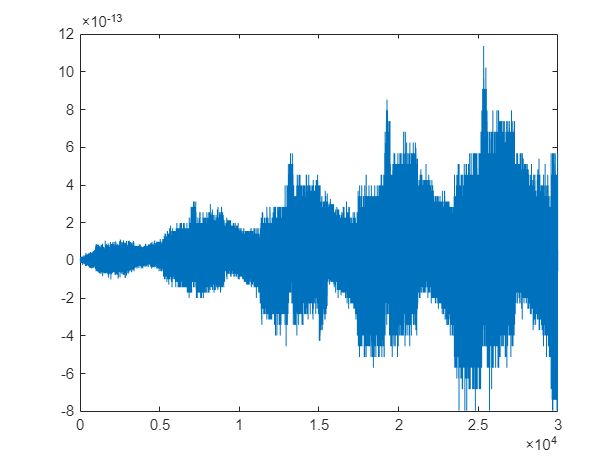

figure; plot(t, yJ3B - y_t)

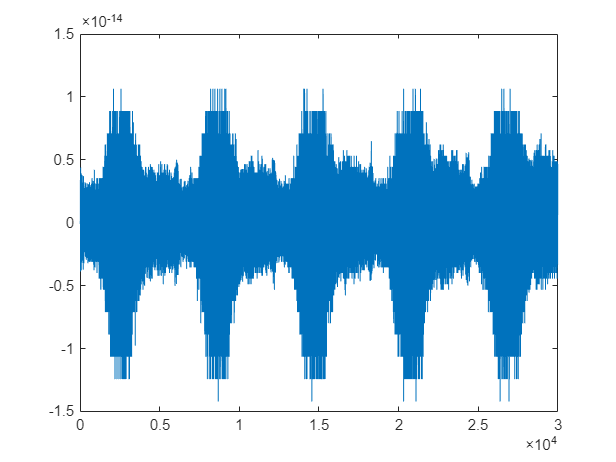

figure; plot(t, zJ3B - z_t)

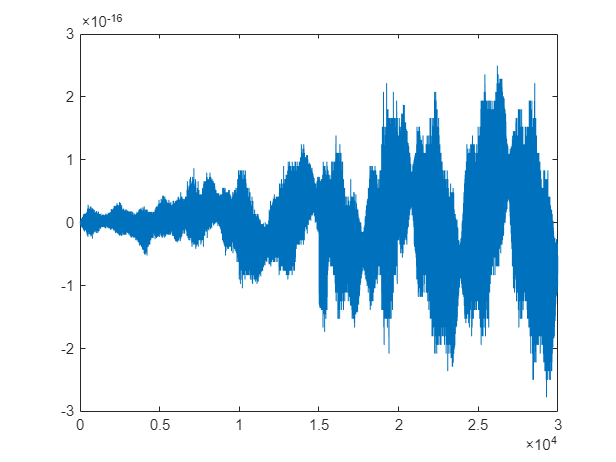




xdotJ3B = (-(1152.*a.^2.*n.^2.*sin(n.*t) - 5760.*a.^2.*e.^2.*n.^2.*sin(n.*t) + 11520.*a.^2.*e.^4.*n.^2.*sin(n.*t) - 11520.*a.^2.*e.^6.*n.^2.*sin(n.*t) + 5760.*a.^2.*e.^8.*n.^2.*sin(n.*t) - 1152.*a.^2.*e.^10.*n.^2.*sin(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*x0 + (-(384.*a.^2.*n.*cos(n.*t) - 1920.*a.^2.*e.^2.*n.*cos(n.*t) + 3840.*a.^2.*e.^4.*n.*cos(n.*t) - 3840.*a.^2.*e.^6.*n.*cos(n.*t) + 1920.*a.^2.*e.^8.*n.*cos(n.*t) - 384.*a.^2.*e.^10.*n.*cos(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*dx0 + (-(768.*a.^2.*n.*sin(n.*t) - 3840.*a.^2.*e.^2.*n.*sin(n.*t) + 7680.*a.^2.*e.^4.*n.*sin(n.*t) - 7680.*a.^2.*e.^6.*n.*sin(n.*t) + 3840.*a.^2.*e.^8.*n.*sin(n.*t) - 768.*a.^2.*e.^10.*n.*sin(n.*t))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*dy0 + ((360.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(omega) + 72.*R.^3.*e.*n.^2.*sin(INC).*cos(omega) - 45.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t) + 45.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(3.*n.*t) + 360.*R.^3.*e.^2.*n.^2.*sin(INC).*cos(omega).*cos(theta_0) + 108.*R.^3.*n.^2.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 108.*R.^3.*n.^2.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 105.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t) - 105.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t) + 45.*R.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t) - 45.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t) - 45.*R.^3.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(3.*n.*t) - 45.*R.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t) - 8640.*R.^3.*e.^2.*n.^2.*sin(INC).*sin(omega).*sin(theta_0) - 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(omega) - 525.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(n.*t).*sin(INC) + 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*n.*t).*cos(omega) + 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(2.*n.*t).*sin(INC) - 675.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(3.*n.*t).*sin(INC) + 800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(n.*t).*sin(omega) + 1275.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(n.*t).*sin(INC) - 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*n.*t).*sin(omega) - 1200.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(2.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(3.*n.*t).*sin(INC) + 1800.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(omega).*cos(theta_0) + 540.*R.^3.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 540.*R.^3.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 72.*R.^3.*e.*n.^2.*cos(n.*t).*sin(INC).*cos(omega) + 2880.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(omega).*sin(theta_0) - 21600.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*sin(INC).*sin(omega) + 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*n.*t) + 225.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*n.*t) + 234.*R.^3.*e.*n.^2.*sin(n.*t).*sin(INC).*sin(omega) + 135.*R.^3.*n.^2.*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t).*sin(INC) - 135.*R.^3.*n.^2.*cos(3.*omega).*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC) - 425.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(n.*t) + 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*n.*t) - 225.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*n.*t) + 315.*R.^3.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) + 315.*R.^3.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) - 135.*R.^3.*n.^2.*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) + 135.*R.^3.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC) + 135.*R.^3.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC) + 135.*R.^3.*n.^2.*sin(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC) - 360.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(omega) + 8400.*R.^3.*e.^3.*n.^2.*cos(n.*t).*sin(INC).*cos(omega) - 8400.*R.^3.*e.^3.*n.^2.*cos(2.*n.*t).*sin(INC).*cos(omega) + 7200.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(omega) + 1170.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(n.*t).*sin(omega) - 2400.*R.^3.*e.^3.*n.^2.*sin(n.*t).*sin(INC).*sin(omega) + 8400.*R.^3.*e.^3.*n.^2.*sin(2.*n.*t).*sin(INC).*sin(omega) + 360.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + (765.*R.^3.*e.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t).*sin(INC))./2 - 360.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 360.*R.^3.*e.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*cos(2.*n.*t).*sin(INC) + (585.*R.^3.*e.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t).*sin(INC))./2 - (1485.*R.^3.*e.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC))./2 + (135.*R.^3.*e.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC))./2 - 360.*R.^3.*e.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(4.*n.*t).*sin(INC) - 2020.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - (195.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0))./2 - 2370.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 2025.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 220.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) + 1380.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(2.*n.*t).*sin(INC).*cos(theta_0) + 3180.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 6375.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - (2565.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(3.*n.*t).*sin(INC).*cos(theta_0))./2 - 810.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) - 2025.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) + 8400.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 2025.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) + 300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(3.*omega).*sin(n.*t) + 300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(3.*omega).*cos(n.*t) + 810.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 360.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 810.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + (585.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC))./2 + (585.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC))./2 - (765.*R.^3.*e.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC))./2 + 360.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 360.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 360.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 360.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC) + (1125.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC))./2 - 360.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(2.*n.*t).*sin(INC) + (1125.*R.^3.*e.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC))./2 - 360.*R.^3.*e.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC) - (585.*R.^3.*e.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC))./2 + (1485.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC))./2 + (1485.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC))./2 + (1485.*R.^3.*e.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC))./2 - (135.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC))./2 - (135.*R.^3.*e.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC))./2 - (135.*R.^3.*e.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC))./2 + 360.*R.^3.*e.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t).*sin(INC) + 360.*R.^3.*e.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC) + 360.*R.^3.*e.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*sin(INC) - 2660.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 1990.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 1930.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - (1455.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0))./2 + 2220.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + (195.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0))./2 - (1455.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0))./2 + 2370.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 2220.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 3825.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 19575.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 11025.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 220.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) - 220.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) - 220.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) - 1380.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(2.*n.*t).*sin(INC).*sin(theta_0) - 3180.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) - 1380.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*cos(2.*n.*t).*sin(INC).*sin(theta_0) - 1380.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(2.*n.*t).*sin(INC).*cos(theta_0) - 3180.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) - 3180.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 6225.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 6375.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 6225.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + (2565.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(3.*n.*t).*sin(INC).*sin(theta_0))./2 + 810.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) + (2565.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*cos(3.*n.*t).*sin(INC).*sin(theta_0))./2 + (2565.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(3.*n.*t).*sin(INC).*cos(theta_0))./2 + 810.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) + 810.*R.^3.*e.^2.*n.^2.*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) + 2025.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) + 2025.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) + 2025.*R.^3.*e.^3.*n.^2.*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) - 8400.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) - 8400.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) - 8400.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 2025.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) + 2025.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) + 2025.*R.^3.*e.^3.*n.^2.*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) + 630.*R.^3.*e.*n.^3.*t.*sin(3.*INC).*cos(n.*t).*sin(omega) + 630.*R.^3.*e.*n.^3.*t.*sin(3.*INC).*sin(n.*t).*cos(omega) - 14400.*R.^3.*e.^3.*n.^3.*t.*cos(n.*t).*sin(INC).*sin(omega) - 12600.*R.^3.*e.^3.*n.^3.*t.*sin(n.*t).*sin(INC).*cos(omega) - (255.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t))./2 - 120.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(2.*n.*t) - (195.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t))./2 + (495.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(3.*n.*t))./2 - (45.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(3.*n.*t))./2 + 120.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(4.*n.*t) + (65.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*cos(theta_0))./2 + 1750.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) - 120.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t).*sin(INC) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 825.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t).*sin(INC) - 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*n.*t).*cos(theta_0) - 2020.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 420.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(3.*theta_0).*cos(2.*n.*t).*sin(INC) - (225.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(5.*theta_0).*cos(n.*t).*sin(INC))./2 + 2125.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*cos(omega) - 300.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t).*sin(INC) + (855.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*n.*t).*cos(theta_0))./2 + 270.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*cos(omega) + 1080.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*cos(3.*n.*t).*cos(omega) + 2025.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC) - 1380.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(3.*theta_0).*cos(4.*n.*t).*sin(INC) - 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*cos(2.*n.*t).*cos(omega) - 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(2.*theta_0).*cos(4.*n.*t).*sin(INC) - 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(2.*n.*t).*sin(INC) + (1485.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(5.*theta_0).*cos(3.*n.*t).*sin(INC))./2 + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*cos(3.*n.*t).*cos(omega) + 2025.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC) - 420.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(5.*theta_0).*cos(4.*n.*t).*sin(INC) - 210.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*cos(5.*theta_0).*cos(5.*n.*t).*sin(INC) - 525.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(4.*theta_0).*cos(5.*n.*t).*sin(INC) - 675.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(6.*theta_0).*cos(3.*n.*t).*sin(INC) + 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(6.*theta_0).*cos(4.*n.*t).*sin(INC) - 525.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*cos(6.*theta_0).*cos(5.*n.*t).*sin(INC) + 36.*R.^3.*n.^3.*t.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 36.*R.^3.*n.^3.*t.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 36.*R.^3.*n.^3.*t.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - (195.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t))./2 - (195.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t))./2 + (255.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t))./2 + 120.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t) - (375.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t))./2 + 120.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(2.*n.*t) - (375.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t))./2 + 120.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + (195.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t))./2 - (495.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t))./2 - (495.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(3.*n.*t))./2 - (495.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t))./2 + (45.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t))./2 + (45.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(3.*n.*t))./2 + (45.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t))./2 - 120.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t) - 120.*R.^3.*e.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(4.*n.*t) - 120.*R.^3.*e.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t) + (485.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*sin(theta_0))./2 - 2180.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) - (65.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*sin(theta_0))./2 + (485.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*cos(theta_0))./2 - 1750.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) - 2180.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) - 1440.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) - 1440.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 120.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) - 1275.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 6525.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 3675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 2175.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 2175.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 825.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) + 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*n.*t).*sin(theta_0) + 2020.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) + 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*cos(2.*n.*t).*sin(theta_0) + 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*n.*t).*cos(theta_0) + 2020.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) + 2020.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega) - 420.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC) - (1005.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(5.*theta_0).*sin(n.*t).*sin(INC))./2 - 420.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(2.*n.*t).*sin(INC) - (1005.*R.^3.*e.^2.*n.^2.*cos(5.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC))./2 - 420.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC) + (225.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(5.*theta_0).*cos(n.*t).*sin(INC))./2 - 2075.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*sin(omega) - 2125.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*sin(omega) - 2075.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*cos(omega) + 1050.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC) + 1050.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 300.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC) - (855.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*n.*t).*sin(theta_0))./2 - 270.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*sin(omega) - (855.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*cos(3.*n.*t).*sin(theta_0))./2 - (855.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*n.*t).*cos(theta_0))./2 - 270.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*sin(omega) - 270.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*cos(omega) - 1080.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 1080.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC) - 1080.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*n.*t).*sin(omega) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*cos(3.*n.*t).*sin(omega) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(2.*theta_0).*sin(3.*n.*t).*cos(omega) - 2025.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC) - 2025.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC) - 2025.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC) + 1380.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t).*sin(INC) + 1380.*R.^3.*e.^2.*n.^2.*cos(3.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC) + 1380.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t).*sin(INC) + 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(2.*n.*t).*sin(omega) + 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*cos(2.*n.*t).*sin(omega) + 2800.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*sin(2.*n.*t).*cos(omega) + 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t).*sin(INC) + 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC) + 150.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(6.*theta_0).*sin(n.*t).*sin(INC) + 1200.*R.^3.*e.^3.*n.^2.*cos(2.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC) + 1200.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(2.*n.*t).*sin(INC) + 150.*R.^3.*e.^3.*n.^2.*cos(6.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) + 1200.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t).*sin(INC) + 1200.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC) - (1485.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t).*sin(INC))./2 - (1485.*R.^3.*e.^2.*n.^2.*cos(5.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC))./2 - (1485.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t).*sin(INC))./2 - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*n.*t).*sin(omega) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*cos(3.*n.*t).*sin(omega) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(4.*theta_0).*sin(3.*n.*t).*cos(omega) - 2025.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC) - 2025.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC) - 2025.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC) + 420.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t).*sin(INC) + 420.*R.^3.*e.^2.*n.^2.*cos(5.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC) + 420.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t).*sin(INC) + 210.*R.^3.*e.^2.*n.^2.*cos(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t).*sin(INC) + 210.*R.^3.*e.^2.*n.^2.*cos(5.*theta_0).*sin(3.*omega).*sin(5.*n.*t).*sin(INC) + 210.*R.^3.*e.^2.*n.^2.*sin(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t).*sin(INC) + 525.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t).*sin(INC) + 525.*R.^3.*e.^3.*n.^2.*cos(4.*theta_0).*sin(3.*omega).*sin(5.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.^2.*cos(6.*theta_0).*sin(3.*omega).*sin(3.*n.*t).*sin(INC) + 525.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t).*sin(INC) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t).*sin(INC) - 1200.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t).*sin(INC) - 1200.*R.^3.*e.^3.*n.^2.*cos(6.*theta_0).*sin(3.*omega).*sin(4.*n.*t).*sin(INC) - 1200.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t).*sin(INC) + 525.*R.^3.*e.^3.*n.^2.*cos(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t).*sin(INC) + 525.*R.^3.*e.^3.*n.^2.*cos(6.*theta_0).*sin(3.*omega).*sin(5.*n.*t).*sin(INC) + 525.*R.^3.*e.^3.*n.^2.*sin(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t).*sin(INC) - 36.*R.^3.*n.^3.*t.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 72.*R.^3.*e.*n.^2.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 72.*R.^3.*e.*n.^2.*cos(2.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) + 3180.*R.^3.*e.^2.*n.^2.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 3540.*R.^3.*e.^2.*n.^2.*cos(2.*n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 4800.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(n.*t).*sin(omega) + 4200.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(n.*t).*cos(omega) - 900.*R.^3.*e.^3.*n.^3.*t.*cos(3.*omega).*sin(n.*t).*sin(INC) - 900.*R.^3.*e.^3.*n.^3.*t.*sin(3.*omega).*cos(n.*t).*sin(INC) + 40.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(n.*t) + 275.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t) - 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(2.*n.*t) + (75.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*cos(n.*t))./2 + 100.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(n.*t) - 360.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(3.*n.*t) - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(3.*n.*t) + 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*cos(4.*n.*t) + 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(4.*n.*t) + 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(2.*n.*t) - (495.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*cos(3.*n.*t))./2 - 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(3.*n.*t) + 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*cos(4.*n.*t) + 70.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*cos(5.*n.*t) + 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*cos(5.*n.*t) + 225.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*cos(3.*n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*cos(4.*n.*t) + 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*cos(5.*n.*t) + 180.*R.^3.*n.^3.*t.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 180.*R.^3.*n.^3.*t.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 180.*R.^3.*n.^3.*t.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 162.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 72.*R.^3.*e.*n.^2.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 162.*R.^3.*e.*n.^2.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 72.*R.^3.*e.*n.^2.*cos(2.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 72.*R.^3.*e.*n.^2.*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) + 72.*R.^3.*e.*n.^2.*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 5100.*R.^3.*e.^2.*n.^2.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 1650.*R.^3.*e.^2.*n.^2.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 1410.*R.^3.*e.^2.*n.^2.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 3540.*R.^3.*e.^2.*n.^2.*cos(2.*n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 3540.*R.^3.*e.^2.*n.^2.*sin(2.*n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 3540.*R.^3.*e.^2.*n.^2.*sin(2.*n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 480.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(n.*t) + 480.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(n.*t) - 40.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(n.*t) - 725.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t) - 725.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t) - 275.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t) + 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t) + (335.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*sin(n.*t))./2 + 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(2.*n.*t) + (335.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*sin(n.*t))./2 + 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t) - (75.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*cos(n.*t))./2 - 350.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(n.*t) - 350.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(n.*t) - 100.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(n.*t) + 360.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t) + 360.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(3.*n.*t) + 360.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(3.*n.*t) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t) - 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t) - 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*sin(4.*n.*t) - 460.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t) - 50.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*sin(n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(4.*n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(2.*n.*t) - 50.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*sin(n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t) - 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t) + (495.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t))./2 + (495.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*sin(3.*n.*t))./2 + (495.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t))./2 + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(3.*n.*t) + 675.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t) - 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t) - 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*sin(4.*n.*t) - 140.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t) - 70.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t) - 70.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*sin(5.*n.*t) - 70.*R.^3.*e.^2.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t) - 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t) - 225.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t) - 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*sin(5.*n.*t) - 225.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*sin(3.*n.*t) - 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t) - 225.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t) + 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t) + 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*sin(4.*n.*t) + 400.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t) - 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t) - 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*sin(5.*n.*t) - 175.*R.^3.*e.^3.*n.^2.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t) - 180.*R.^3.*n.^3.*t.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 126.*R.^3.*e.*n.^3.*t.*cos(n.*t).*sin(INC).*sin(omega) + 126.*R.^3.*e.*n.^3.*t.*sin(n.*t).*sin(INC).*cos(omega) - 120.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*sin(theta_0) + 1050.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) - 6300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 900.*R.^3.*e.^3.*n.^3.*t.*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 1500.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*sin(omega) + 54.*R.^3.*e.*n.^3.*t.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 54.*R.^3.*e.*n.^3.*t.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 54.*R.^3.*e.*n.^3.*t.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 8730.*R.^3.*e.^2.*n.^3.*t.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 5670.*R.^3.*e.^2.*n.^3.*t.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 4950.*R.^3.*e.^2.*n.^3.*t.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t) + 300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t) + 300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t) - 54.*R.^3.*e.*n.^3.*t.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 9450.*R.^3.*e.^2.*n.^3.*t.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t) + 270.*R.^3.*e.*n.^3.*t.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 270.*R.^3.*e.*n.^3.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 270.*R.^3.*e.*n.^3.*t.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 2430.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 2370.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 2130.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 360.*R.^3.*e.^2.*n.^3.*t.*cos(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0) - 360.*R.^3.*e.^2.*n.^3.*t.*cos(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0) + 1710.*R.^3.*e.^2.*n.^3.*t.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 1710.*R.^3.*e.^2.*n.^3.*t.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 360.*R.^3.*e.^2.*n.^3.*t.*sin(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0) + 1710.*R.^3.*e.^2.*n.^3.*t.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 9900.*R.^3.*e.^3.*n.^3.*t.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 8100.*R.^3.*e.^3.*n.^3.*t.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 17100.*R.^3.*e.^3.*n.^3.*t.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 4500.*R.^3.*e.^3.*n.^3.*t.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 4500.*R.^3.*e.^3.*n.^3.*t.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 4500.*R.^3.*e.^3.*n.^3.*t.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 270.*R.^3.*e.*n.^3.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 2670.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 360.*R.^3.*e.^2.*n.^3.*t.*sin(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0) - 1710.*R.^3.*e.^2.*n.^3.*t.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 18900.*R.^3.*e.^3.*n.^3.*t.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 4500.*R.^3.*e.^3.*n.^3.*t.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 120.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*sin(theta_0) + 120.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*cos(theta_0) - 1050.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) - 1050.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) + 120.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*cos(theta_0) - 1050.*R.^3.*e.^2.*n.^3.*t.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) + 3300.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 2700.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 5700.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) - 900.*R.^3.*e.^3.*n.^3.*t.*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t).*sin(INC) - 900.*R.^3.*e.^3.*n.^3.*t.*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 900.*R.^3.*e.^3.*n.^3.*t.*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 1500.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*sin(omega) - 1500.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*cos(omega) - 1500.*R.^3.*e.^3.*n.^3.*t.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*cos(omega))./(a.^2.*n.*(- 1 + e.^2).^5.*384)).*J3;
ydotJ3B = ((2304.*a.^2.*n - 2304.*a.^2.*n.*cos(n.*t) - 11520.*a.^2.*e.^2.*n + 23040.*a.^2.*e.^4.*n - 23040.*a.^2.*e.^6.*n + 11520.*a.^2.*e.^8.*n - 2304.*a.^2.*e.^10.*n + 11520.*a.^2.*e.^2.*n.*cos(n.*t) - 23040.*a.^2.*e.^4.*n.*cos(n.*t) + 23040.*a.^2.*e.^6.*n.*cos(n.*t) - 11520.*a.^2.*e.^8.*n.*cos(n.*t) + 2304.*a.^2.*e.^10.*n.*cos(n.*t))./(a.^2.*(- 1 + e.^2).^5.*384)).*x0 + ((768.*sin(n.*t).*a.^2 - 3840.*sin(n.*t).*a.^2.*e.^2 + 7680.*sin(n.*t).*a.^2.*e.^4 - 7680.*sin(n.*t).*a.^2.*e.^6 + 3840.*sin(n.*t).*a.^2.*e.^8 - 768.*sin(n.*t).*a.^2.*e.^10)./(a.^2.*(- 1 + e.^2).^5.*384)).*dx0 + ((1152.*a.^2 - 1536.*a.^2.*cos(n.*t) - 5760.*a.^2.*e.^2 + 11520.*a.^2.*e.^4 - 11520.*a.^2.*e.^6 + 5760.*a.^2.*e.^8 - 1152.*a.^2.*e.^10 + 7680.*a.^2.*e.^2.*cos(n.*t) - 15360.*a.^2.*e.^4.*cos(n.*t) + 15360.*a.^2.*e.^6.*cos(n.*t) - 7680.*a.^2.*e.^8.*cos(n.*t) + 1536.*a.^2.*e.^10.*cos(n.*t))./(a.^2.*(- 1 + e.^2).^5.*384)).*dy0 + (-(2700.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(INC) - 180.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega) - 8100.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(omega) - 180.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0) + 540.*R.^3.*n.*sin(3.*INC).*cos(omega).*sin(theta_0) + 540.*R.^3.*n.*sin(3.*INC).*cos(theta_0).*sin(omega) + 90.*R.^3.*e.*n.*sin(INC).*sin(omega) - 900.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega) + 540.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(INC) + 540.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(INC) + 450.*R.^3.*e.*n.*sin(3.*INC).*sin(omega) + 24300.*R.^3.*e.^3.*n.*sin(INC).*sin(omega) + 108.*R.^3.*n.*sin(INC).*cos(omega).*sin(theta_0) + 108.*R.^3.*n.*sin(INC).*cos(theta_0).*sin(omega) + 1080.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(omega) + 1080.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(omega) + 540.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(INC) + 540.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(INC) + 945.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(INC) + 945.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(INC) - 7755.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(omega).*sin(theta_0) - 8415.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(theta_0).*sin(omega) - 945.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(INC).*sin(theta_0) - 1215.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(INC).*sin(omega) - 945.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(INC).*cos(theta_0) - 1215.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(INC).*cos(omega) + 21600.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(INC).*sin(omega) + 50400.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(INC).*cos(omega) - 2700.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(INC).*sin(omega) - 2700.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(INC).*cos(omega) - 540.*R.^3.*n.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 90.*R.^3.*e.*n.*cos(n.*t).*sin(INC).*sin(omega) + 234.*R.^3.*e.*n.*sin(n.*t).*sin(INC).*cos(omega) + 50.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(n.*t) + 550.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*cos(n.*t) + 500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*n.*t) + 500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*cos(2.*n.*t) - 150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*n.*t) - 150.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*cos(3.*n.*t) + 108.*R.^3.*e.*n.^2.*t.*sin(INC).*cos(omega) + 270.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t).*sin(INC) - 630.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) - 630.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + 90.*R.^3.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC) + 90.*R.^3.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC) + 90.*R.^3.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 180.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0) - 180.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega) - 315.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0) - 315.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega) + 315.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(theta_0) - 315.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(omega) + 315.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(theta_0) - 315.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(omega) - (4995.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*sin(INC))./2 - (4995.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*sin(INC))./2 - 7200.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(omega) - 16800.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(omega) + 4050.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*sin(INC) + 4050.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*sin(INC) - (1809.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*sin(INC))./2 - (1809.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*sin(INC))./2 + 900.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(omega) + 900.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(omega) + 1620.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*sin(INC) + 1620.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*sin(INC) + 270.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*sin(INC) + 270.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*sin(INC) - 270.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) - 90.*R.^3.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 450.*R.^3.*e.*n.*sin(3.*INC).*cos(n.*t).*sin(omega) + 1170.*R.^3.*e.*n.*sin(3.*INC).*sin(n.*t).*cos(omega) - 13200.*R.^3.*e.^3.*n.*cos(n.*t).*sin(INC).*sin(omega) - 3000.*R.^3.*e.^3.*n.*sin(n.*t).*sin(INC).*cos(omega) - 11100.*R.^3.*e.^3.*n.*cos(2.*n.*t).*sin(INC).*sin(omega) - 11100.*R.^3.*e.^3.*n.*sin(2.*n.*t).*sin(INC).*cos(omega) - 108.*R.^3.*n.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 108.*R.^3.*n.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 108.*R.^3.*n.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 540.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(omega) - 90.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t) + 210.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t) + 210.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t) - 30.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t) - 30.*R.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t) - 30.*R.^3.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 216.*R.^3.*e.*n.*cos(2.*theta_0).*sin(INC).*sin(omega) + 216.*R.^3.*e.*n.*sin(2.*theta_0).*sin(INC).*cos(omega) + 21105.*R.^3.*e.^2.*n.*sin(INC).*cos(omega).*sin(theta_0) + 8685.*R.^3.*e.^2.*n.*sin(INC).*cos(theta_0).*sin(omega) - 108.*R.^3.*n.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + (1665.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0))./2 + (1665.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega))./2 - 1350.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0) - 1350.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega) + (603.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0))./2 + (603.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega))./2 - 540.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0) - 540.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega) - 90.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0) - 90.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega) + 90.*R.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t) + 30.*R.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t) + 4400.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(n.*t).*sin(omega) + 1000.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(n.*t).*cos(omega) - 150.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(n.*t).*sin(INC) - 1650.*R.^3.*e.^3.*n.*sin(3.*omega).*cos(n.*t).*sin(INC) + 3700.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*n.*t).*sin(omega) + 3700.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*n.*t).*cos(omega) - 1500.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*n.*t).*sin(INC) - 1500.*R.^3.*e.^3.*n.*sin(3.*omega).*cos(2.*n.*t).*sin(INC) + 450.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(3.*n.*t).*sin(INC) + 450.*R.^3.*e.^3.*n.*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 540.*R.^3.*n.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 540.*R.^3.*n.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 540.*R.^3.*n.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*cos(n.*t) + 252.*R.^3.*e.*n.^2.*t.*sin(n.*t).*sin(INC).*sin(omega) - 255.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t) + 195.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t) + 195.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t) + 150.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(2.*n.*t) - 195.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t) + 150.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t) + 375.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t) + 150.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(2.*n.*t) + 375.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t) - 165.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t) - 165.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t) - 165.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 15.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t) + 15.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t) + 15.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t) - 75.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(4.*n.*t) - 75.*R.^3.*e.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t) - 75.*R.^3.*e.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(4.*n.*t) - 605.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*sin(theta_0) - 55.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*cos(theta_0) + 2170.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) + 1310.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) - 605.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*cos(theta_0) + 2170.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) - 240.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t).*sin(INC) + 2880.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t).*sin(INC) + 2880.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + 6450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 3150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 16050.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) - 750.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t).*sin(INC) - 3450.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 3450.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + 575.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*n.*t).*sin(theta_0) + 575.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*n.*t).*cos(theta_0) - 2155.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) - 2155.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 575.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(2.*n.*t).*cos(theta_0) - 2155.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 525.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(2.*n.*t).*sin(INC) - 225.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(n.*t).*sin(INC) - 525.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC) + 1005.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(n.*t).*sin(INC) - 525.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(2.*n.*t).*sin(INC) + 1005.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + 2050.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*sin(omega) + 2150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*cos(omega) + 2050.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*cos(omega) - 600.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t).*sin(INC) - 2100.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC) - 2100.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 285.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*n.*t).*sin(theta_0) - 285.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*n.*t).*cos(theta_0) + 300.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*cos(3.*n.*t).*sin(omega) + 300.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*n.*t).*cos(omega) - 285.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*cos(3.*n.*t).*cos(theta_0) + 300.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*cos(3.*n.*t).*cos(omega) - 720.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 720.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC) - 720.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + 750.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(3.*n.*t).*sin(omega) + 750.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*n.*t).*cos(omega) + 750.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(3.*n.*t).*cos(omega) - 1350.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC) - 1350.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC) - 1350.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + (1725.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*theta_0).*sin(4.*n.*t).*sin(INC))./2 + (1725.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t).*sin(INC))./2 + (1725.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC))./2 - 3700.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(2.*n.*t).*sin(omega) - 3700.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(2.*n.*t).*cos(omega) - 3700.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(2.*n.*t).*cos(omega) + 750.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(4.*n.*t).*sin(INC) + 1500.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(2.*n.*t).*sin(INC) + 750.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t).*sin(INC) + 1500.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC) - 300.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(n.*t).*sin(INC) + 750.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) + 1500.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(2.*n.*t).*sin(INC) - 300.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 495.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(3.*n.*t).*sin(INC) - 495.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t).*sin(INC) - 495.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + 750.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*cos(3.*n.*t).*sin(omega) + 750.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*n.*t).*cos(omega) + 750.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*cos(3.*n.*t).*cos(omega) - 1350.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC) - 1350.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC) - 1350.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + (525.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(4.*n.*t).*sin(INC))./2 + (525.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t).*sin(INC))./2 + (525.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC))./2 + 132.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(5.*theta_0).*sin(5.*n.*t).*sin(INC) + 132.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t).*sin(INC) + 132.*R.^3.*e.^2.*n.*cos(5.*theta_0).*sin(3.*omega).*cos(5.*n.*t).*sin(INC) + 330.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(5.*n.*t).*sin(INC) + 450.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(3.*n.*t).*sin(INC) + 330.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t).*sin(INC) + 450.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t).*sin(INC) + 330.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(5.*n.*t).*sin(INC) + 450.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 750.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(4.*n.*t).*sin(INC) - 750.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t).*sin(INC) - 750.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) + 330.*R.^3.*e.^3.*n.*cos(3.*omega).*cos(6.*theta_0).*sin(5.*n.*t).*sin(INC) + 330.*R.^3.*e.^3.*n.*cos(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t).*sin(INC) + 330.*R.^3.*e.^3.*n.*cos(6.*theta_0).*sin(3.*omega).*cos(5.*n.*t).*sin(INC) + 600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*sin(n.*t) + 255.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t) - 150.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t) + 195.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t) + 165.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t) - 15.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t) + 75.*R.^3.*e.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t) + 55.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*sin(theta_0) - 1310.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) + 240.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t).*sin(INC) - 21150.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 750.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) - 575.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*n.*t).*sin(theta_0) + 2155.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) + 525.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC) + 225.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(n.*t).*sin(INC) - 2150.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*sin(omega) + 600.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC) + 285.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*n.*t).*sin(theta_0) - 300.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*theta_0).*sin(3.*n.*t).*sin(omega) + 720.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC) - 750.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(3.*n.*t).*sin(omega) + 1350.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC) - (1725.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t).*sin(INC))./2 + 3700.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(2.*n.*t).*sin(omega) - 750.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t).*sin(INC) - 1500.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC) + 495.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t).*sin(INC) - 750.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(4.*theta_0).*sin(3.*n.*t).*sin(omega) + 1350.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC) - (525.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t).*sin(INC))./2 - 132.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t).*sin(INC) - 330.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t).*sin(INC) - 450.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t).*sin(INC) + 750.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t).*sin(INC) - 330.*R.^3.*e.^3.*n.*sin(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t).*sin(INC) - 1260.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega) + 25200.*R.^3.*e.^3.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega) + 10800.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(omega) - 72.*R.^3.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 162.*R.^3.*e.*n.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 306.*R.^3.*e.*n.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 162.*R.^3.*e.*n.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 54.*R.^3.*e.*n.*cos(2.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) - 54.*R.^3.*e.*n.*cos(2.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) - 54.*R.^3.*e.*n.*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 16530.*R.^3.*e.^2.*n.*cos(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 4110.*R.^3.*e.^2.*n.*cos(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 1290.*R.^3.*e.^2.*n.*sin(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 4575.*R.^3.*e.^2.*n.*cos(2.*n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 4575.*R.^3.*e.^2.*n.*cos(2.*n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 4575.*R.^3.*e.^2.*n.*sin(2.*n.*t).*sin(INC).*cos(omega).*cos(theta_0) + 1260.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*sin(omega) - 28800.*R.^3.*e.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*sin(omega) + 80.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(n.*t) - 960.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(n.*t) - 960.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(n.*t) + 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t) + 1150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t) + 1150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t) + 175.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(2.*n.*t) + 75.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(n.*t) + 175.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(2.*n.*t) - 335.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(n.*t) + 175.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(2.*n.*t) - 335.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(n.*t) + 200.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t) + 700.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t) + 700.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t) + 240.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(3.*n.*t) + 240.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(3.*n.*t) + 240.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t) + 450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t) + 450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t) - (575.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(3.*theta_0).*sin(4.*n.*t))./2 - (575.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(3.*theta_0).*cos(4.*n.*t))./2 - (575.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*theta_0).*sin(3.*omega).*cos(4.*n.*t))./2 - 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*sin(4.*n.*t) - 500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(2.*n.*t) - 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*cos(4.*n.*t) - 500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(2.*n.*t) + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(n.*t) - 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*cos(4.*n.*t) - 500.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(2.*n.*t) + 100.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(n.*t) + 165.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(3.*n.*t) + 165.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(3.*n.*t) + 165.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t) + 450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t) + 450.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t) - (175.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(4.*n.*t))./2 - (175.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(4.*n.*t))./2 - (175.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(4.*n.*t))./2 - 44.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*cos(5.*theta_0).*sin(5.*n.*t) - 44.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(3.*omega).*sin(5.*theta_0).*cos(5.*n.*t) - 44.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(5.*theta_0).*sin(3.*omega).*cos(5.*n.*t) - 110.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(4.*theta_0).*sin(5.*n.*t) - 150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*sin(3.*n.*t) - 110.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(4.*theta_0).*cos(5.*n.*t) - 150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(3.*n.*t) - 110.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(4.*theta_0).*sin(3.*omega).*cos(5.*n.*t) - 150.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(3.*n.*t) + 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*sin(4.*n.*t) + 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(4.*n.*t) + 250.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(4.*n.*t) - 110.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*cos(6.*theta_0).*sin(5.*n.*t) - 110.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(3.*omega).*sin(6.*theta_0).*cos(5.*n.*t) - 110.*R.^3.*e.^3.*n.*sin(3.*INC).*cos(6.*theta_0).*sin(3.*omega).*cos(5.*n.*t) + 540.*R.^3.*e.^2.*n.^2.*t.*sin(INC).*cos(omega).*cos(theta_0) + 72.*R.^3.*n.^2.*t.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 72.*R.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) + 72.*R.^3.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) - 306.*R.^3.*e.*n.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 54.*R.^3.*e.*n.*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 22710.*R.^3.*e.^2.*n.*sin(n.*t).*sin(INC).*sin(omega).*sin(theta_0) + 4575.*R.^3.*e.^2.*n.*sin(2.*n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 80.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(n.*t) - 250.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t) - 175.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(2.*n.*t) - 75.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(n.*t) - 200.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t) - 240.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(3.*n.*t) - 450.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t) + (575.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(3.*theta_0).*sin(4.*n.*t))./2 + 250.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*sin(4.*n.*t) + 500.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(2.*n.*t) - 165.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(3.*n.*t) - 450.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t) + (175.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(4.*n.*t))./2 + 44.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(3.*omega).*sin(5.*theta_0).*sin(5.*n.*t) + 110.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(4.*theta_0).*sin(5.*n.*t) + 150.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*sin(3.*n.*t) - 250.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*sin(4.*n.*t) + 110.*R.^3.*e.^3.*n.*sin(3.*INC).*sin(3.*omega).*sin(6.*theta_0).*sin(5.*n.*t) - 12960.*R.^3.*e.^2.*n.^2.*t.*sin(INC).*sin(omega).*sin(theta_0) - 8400.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega) + 1800.*R.^3.*e.^3.*n.^2.*t.*cos(3.*omega).*cos(n.*t).*sin(INC) - 360.*R.^3.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 810.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 1530.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 810.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 765.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(n.*t).*sin(INC) - 585.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 585.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) - 270.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) - 270.*R.^3.*e.*n.*sin(3.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 270.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 450.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(2.*n.*t).*sin(INC) + 585.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(n.*t).*sin(INC) - 450.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(2.*n.*t).*sin(INC) - 1125.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(n.*t).*sin(INC) - 450.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(2.*n.*t).*sin(INC) - 1125.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(n.*t).*sin(INC) + 495.*R.^3.*e.*n.*cos(3.*omega).*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC) + 495.*R.^3.*e.*n.*cos(3.*omega).*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC) + 495.*R.^3.*e.*n.*cos(2.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) - 45.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC) - 45.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC) - 45.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(3.*n.*t).*sin(INC) + 225.*R.^3.*e.*n.*cos(3.*omega).*cos(4.*theta_0).*sin(4.*n.*t).*sin(INC) + 225.*R.^3.*e.*n.*cos(3.*omega).*sin(4.*theta_0).*cos(4.*n.*t).*sin(INC) + 225.*R.^3.*e.*n.*cos(4.*theta_0).*sin(3.*omega).*cos(4.*n.*t).*sin(INC) + 6950.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 7610.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 50.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 1815.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0) + 165.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0) - 2190.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 2490.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 1815.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0) - 2190.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 19350.*R.^3.*e.^3.*n.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 9450.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 48150.*R.^3.*e.^3.*n.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 805.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 805.*R.^3.*e.^2.*n.*sin(3.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 805.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) - 1725.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(2.*n.*t).*sin(INC).*sin(theta_0) - 1725.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(2.*n.*t).*sin(INC).*cos(theta_0) + 4305.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) + 4305.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) - 1725.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(2.*n.*t).*sin(INC).*cos(theta_0) + 4305.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 6150.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 6450.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 6150.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 855.*R.^3.*e.^2.*n.*cos(3.*omega).*cos(3.*n.*t).*sin(INC).*sin(theta_0) + 855.*R.^3.*e.^2.*n.*cos(3.*omega).*sin(3.*n.*t).*sin(INC).*cos(theta_0) - 900.*R.^3.*e.^2.*n.*cos(3.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) - 900.*R.^3.*e.^2.*n.*cos(3.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) + 855.*R.^3.*e.^2.*n.*sin(3.*omega).*cos(3.*n.*t).*sin(INC).*cos(theta_0) - 900.*R.^3.*e.^2.*n.*sin(3.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) - 2250.*R.^3.*e.^3.*n.*cos(2.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) - 2250.*R.^3.*e.^3.*n.*cos(2.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) - 2250.*R.^3.*e.^3.*n.*sin(2.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) + 11100.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(2.*n.*t).*sin(INC).*sin(omega) + 11100.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(2.*n.*t).*sin(INC).*cos(omega) + 11100.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(2.*n.*t).*sin(INC).*cos(omega) - 2250.*R.^3.*e.^3.*n.*cos(4.*theta_0).*cos(3.*n.*t).*sin(INC).*sin(omega) - 2250.*R.^3.*e.^3.*n.*cos(4.*theta_0).*sin(3.*n.*t).*sin(INC).*cos(omega) - 2250.*R.^3.*e.^3.*n.*sin(4.*theta_0).*cos(3.*n.*t).*sin(INC).*cos(omega) + 9600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*sin(omega) - 1800.*R.^3.*e.^3.*n.^2.*t.*sin(3.*omega).*sin(n.*t).*sin(INC) + 2700.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(omega).*cos(theta_0) + 360.*R.^3.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 360.*R.^3.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 360.*R.^3.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 1530.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 765.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) + 270.*R.^3.*e.*n.*sin(3.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 450.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(2.*n.*t).*sin(INC) - 585.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(n.*t).*sin(INC) - 495.*R.^3.*e.*n.*sin(3.*omega).*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC) + 45.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC) - 225.*R.^3.*e.*n.*sin(3.*omega).*sin(4.*theta_0).*sin(4.*n.*t).*sin(INC) - 8050.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 165.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0) + 2490.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 63450.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 805.*R.^3.*e.^2.*n.*sin(3.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0) + 1725.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(2.*n.*t).*sin(INC).*sin(theta_0) - 4305.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 6450.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 855.*R.^3.*e.^2.*n.*sin(3.*omega).*sin(3.*n.*t).*sin(INC).*sin(theta_0) + 900.*R.^3.*e.^2.*n.*sin(3.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) + 2250.*R.^3.*e.^3.*n.*sin(2.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) - 11100.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(2.*n.*t).*sin(INC).*sin(omega) + 2250.*R.^3.*e.^3.*n.*sin(4.*theta_0).*sin(3.*n.*t).*sin(INC).*sin(omega) - 252.*R.^3.*e.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega) + 4320.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(omega).*sin(theta_0) - 32400.*R.^3.*e.^3.*n.^2.*t.*sin(2.*theta_0).*sin(INC).*sin(omega) + 240.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*sin(n.*t).*sin(theta_0) - 2100.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 240.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*cos(n.*t).*sin(theta_0) + 240.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*sin(n.*t).*cos(theta_0) - 2100.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) - 2100.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) + 6600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 12600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 11400.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) - 1800.*R.^3.*e.^3.*n.^2.*t.*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t).*sin(INC) - 1800.*R.^3.*e.^3.*n.^2.*t.*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t).*sin(INC) - 1800.*R.^3.*e.^3.*n.^2.*t.*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t).*sin(INC) - 3000.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(4.*theta_0).*sin(n.*t).*sin(omega) - 3000.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(4.*theta_0).*cos(n.*t).*sin(omega) - 3000.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(4.*theta_0).*sin(n.*t).*cos(omega) - 108.*R.^3.*e.*n.^2.*t.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 9900.*R.^3.*e.^2.*n.^2.*t.*cos(n.*t).*sin(INC).*cos(omega).*cos(theta_0) - 600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t) + 108.*R.^3.*e.*n.^2.*t.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 108.*R.^3.*e.*n.^2.*t.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 108.*R.^3.*e.*n.^2.*t.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 18900.*R.^3.*e.^2.*n.^2.*t.*cos(n.*t).*sin(INC).*sin(omega).*sin(theta_0) - 17460.*R.^3.*e.^2.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(omega).*sin(theta_0) - 11340.*R.^3.*e.^2.*n.^2.*t.*sin(n.*t).*sin(INC).*cos(theta_0).*sin(omega) + 600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*sin(2.*theta_0).*sin(n.*t) + 600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(3.*omega).*sin(n.*t) + 600.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*sin(3.*omega).*sin(2.*theta_0).*cos(n.*t) - 540.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 4260.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) + 720.*R.^3.*e.^2.*n.^2.*t.*cos(3.*omega).*cos(n.*t).*sin(INC).*cos(theta_0) - 3420.*R.^3.*e.^2.*n.^2.*t.*cos(3.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 16200.*R.^3.*e.^3.*n.^2.*t.*cos(2.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) - 9000.*R.^3.*e.^3.*n.^2.*t.*cos(4.*theta_0).*cos(n.*t).*sin(INC).*cos(omega) + 540.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) + 540.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) + 540.*R.^3.*e.*n.^2.*t.*sin(3.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 5340.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 4860.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) + 4740.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 720.*R.^3.*e.^2.*n.^2.*t.*cos(3.*omega).*sin(n.*t).*sin(INC).*sin(theta_0) + 3420.*R.^3.*e.^2.*n.^2.*t.*cos(3.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 720.*R.^3.*e.^2.*n.^2.*t.*sin(3.*omega).*cos(n.*t).*sin(INC).*sin(theta_0) - 720.*R.^3.*e.^2.*n.^2.*t.*sin(3.*omega).*sin(n.*t).*sin(INC).*cos(theta_0) + 3420.*R.^3.*e.^2.*n.^2.*t.*sin(3.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 3420.*R.^3.*e.^2.*n.^2.*t.*sin(3.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 19800.*R.^3.*e.^3.*n.^2.*t.*cos(2.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) - 37800.*R.^3.*e.^3.*n.^2.*t.*sin(2.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) - 34200.*R.^3.*e.^3.*n.^2.*t.*sin(2.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) + 9000.*R.^3.*e.^3.*n.^2.*t.*cos(4.*theta_0).*sin(n.*t).*sin(INC).*sin(omega) + 9000.*R.^3.*e.^3.*n.^2.*t.*sin(4.*theta_0).*cos(n.*t).*sin(INC).*sin(omega) + 9000.*R.^3.*e.^3.*n.^2.*t.*sin(4.*theta_0).*sin(n.*t).*sin(INC).*cos(omega) - 240.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*omega).*cos(n.*t).*cos(theta_0) + 2100.*R.^3.*e.^2.*n.^2.*t.*sin(3.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) - 5400.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 1800.*R.^3.*e.^3.*n.^2.*t.*cos(3.*omega).*cos(2.*theta_0).*cos(n.*t).*sin(INC) + 3000.*R.^3.*e.^3.*n.^2.*t.*sin(3.*INC).*cos(4.*theta_0).*cos(n.*t).*cos(omega))./(a.^2.*(- 1 + e.^2).^5.*384)).*J3;
zdotJ3B = (15.*J3.*R.^3.*cos(INC).*sin(INC).^2.*((n.*sin(n.*t))./2 + (n.*sin(2.*omega + 2.*theta_0 + n.*t))./4 + (n.*sin(2.*omega + 2.*theta_0 - n.*t))./12 - (n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t))./3 + (5.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t))./4 - (5.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t))./16 - (5.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t))./24 - (15.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t))./16 - (e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t))./16 + (15.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t))./16 - (2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 4.*n.*t))./3 + (5.*e.^2.*n.*sin(2.*omega + n.*t))./8 - (5.*e.^2.*n.*sin(2.*omega - n.*t))./8 + (7.*e.*n.*sin(2.*omega + theta_0 + n.*t))./16 + (11.*e.*n.*sin(2.*omega + theta_0 - n.*t))./48 - (2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t))./3 + (5.*e.*n.*sin(theta_0 + n.*t))./8 - (5.*e.*n.*sin(theta_0 - n.*t))./8 + (e.*n.*sin(2.*omega + 3.*theta_0 + n.*t))./16 + (11.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t))./96 + (2.*e.*n.*sin(2.*omega + 3.*theta_0 + 2.*n.*t))./3 - (27.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t))./32 + (5.*e.^2.*n.^2.*t.*cos(2.*omega + 2.*theta_0 + n.*t))./4 - (5.*e.^2.*n.^2.*t.*cos(2.*omega + n.*t))./4 - (e.*n.^2.*t.*cos(2.*omega + theta_0 + n.*t))./8 + (5.*e.*n.^2.*t.*cos(theta_0 + n.*t))./4))./(2.*a.^2.*(e.^2 - 1).^5) - (3.*J3.*R.^3.*cos(INC).*(e.*((5.*n.*sin(theta_0 + n.*t))./2 + (5.*n.^2.*t.*cos(theta_0 + n.*t))./2 - (5.*n.*cos(n.*t).*sin(theta_0))./2) + 2.*n.*cos((n.*t)./2).*sin((n.*t)./2)))./(2.*a.^2.*(e.^2 - 1).^5);

x_dot = 3.*n.*sin(2*eta).*x0 ...
        + cos(2*eta).*dx0 ...
        + 2.*sin(2*eta).*dy0 ...
        + n*R^3*J3/(768*a^2*(e^2 - 1)^5) .* ( ...
                + 40*e.^3.*sin(INC).^3.*( ...
                    - 45*cos(3*beta17) ...
                    - 540*cos(beta17) ...
                    - 45*cos(beta21) ...
                    - 135*cos(beta36) ...
                    - 5*cos(beta37) ...
                    - 80*cos(beta38) ...
                    - 35*cos(beta39) ...
                    + 5*cos(beta40) ...
                    - 420*cos(beta45) ...
                    + 560*cos(beta46) ...
                    - 135*cos(beta47) ...
                    - 5*cos(beta48) ...
                    - 100*cos(beta49) ...
                    + 135*cos(beta51) ...
                    + 80*cos(beta52) ...
                    + 45*cos(beta53) ...
                    - 45*cos(beta54) ...
                    - 80*cos(beta55) ...
                    + 135*cos(beta56) ...
                    - 35*cos(beta58) ...
                    + 25*cos(beta59) ...
                    + 480*cos(beta69) ...
                    + 240*cos(beta70) ...
                    - 45*cos(3*o2) ...
                    + 360.*cos(o2) ...
                    + 200*cos(o4) ...
                    - 560*cos(o5) ...
                    - 60*cos(o6) ...
                    + 25*cos(o8) ...
                    + 80*cos(o7) ...
                    + 720.*cos(alpha4) ...
                    - 720*cos(alpha13) ...
                    - 120*eta.*( ...
                        + 15*sin(beta17) ...
                        - 5*sin(beta45) ...
                        + sin(beta49) ...
                        - 5*sin(beta69) ...
                        + sin(beta70) ...
                        + 15*sin(o2) ...
                        + sin(o4) ...
                        + sin(o6) ...
                    ) ...
                ) ...
                - e.^2.*( ...
                   - sin(3.*INC).*( ...
                    - 720*cos(3*beta5) ...
                    + 2280*cos(beta5) ...
                    + 440*cos(beta7) ...
                    - 1640*cos(beta9) ...
                    - 2370*cos(beta26) ...
                    - 2310*cos(beta27) ...
                    - 440*cos(beta28) ...
                    - 280*cos(beta29) ... 
                    + 920*cos(beta31) ...
                    + 520*cos(beta32) ...
                    - 210*cos(beta41) ...
                    - 920*cos(beta42) ...
                    + 855*cos(beta43) ...
                    + 275*cos(beta44) ...
                    - 130*cos(beta60) ...    
                    - 495*cos(beta61) ...
                    + 280*cos(beta62) ...
                    + 140*cos(beta63) ...  
                    + 205*cos(beta64) ...    
                    + 3930*cos(beta65) ...
                    - 4040*cos(beta66) ...
                    + 540*cos(beta67) ...
                    - 430*cos(beta68) ...
                    - 1080*cos(alpha1) ...   
                    + 4680*cos(alpha6) ...
                   ) ...
                + 3.*sin(INC).*( ...
                    - 720*cos(3*beta5) ...
                    + 360*cos(beta5) ...
                    + 2360*cos(beta7) ...
                    + 280*cos(beta9) ...
                    - 1890*cos(beta26) ...
                    - 870*cos(beta27) ...
                    - 440*cos(beta28) ...
                    - 280*cos(beta29) ...
                    + 920*cos(beta31) ...
                    + 520*cos(beta32) ...
                    - 210*cos(beta41) ...
                    - 920*cos(beta42) ...
                    + 855*cos(beta43) ...
                    + 275*cos(beta44) ...
                    - 130*cos(beta60) ...
                    - 495*cos(beta61) ...
                    + 280*cos(beta62) ...
                    + 140*cos(beta63) ...
                    + 205*cos(beta64) ...
                    + 1530*cos(beta65) ...
                    - 2120*cos(beta66) ...
                    + 540*cos(beta67) ...
                    + 50*cos(beta68) ...
                    - 3000*cos(alpha1) ...
                    + 2760*cos(alpha6) ...
                ) ...
                + 120*eta.*( ...
                    + sin(3*INC)*( ...
                        - 80*sin(beta5) ...
                        + 5*sin(beta26) ...
                        - 4*sin(beta27) ...
                        - 4*sin(beta41) ...
                        + 35*sin(beta65) ...
                        ) ...
                    - 3*sin(INC)*( ...
                        - 80*sin(beta5) ...
                        + 21*sin(beta26) ...
                        - 4*sin(beta27) ...
                        - 4*sin(beta41) ...
                        + 19*sin(beta65) ...
                        ) ...
                    ) ...
                ) ...
                + e.*( ...
                    + 15.*sin(3.*INC).*( ...
                        - 48*cos(beta19) ...
                        - 16*cos(beta50) ...
                        + 33*cos(beta51) ...
                        - 3*cos(beta56) ...
                        + 16*cos(beta57) ...
                        - 18*cos(o2) ...
                        + 54*cos(o4) ...
                        + 72*sin(alpha4).*sin(2*eta) ...
                        - 13*sin(alpha8).*sin(2*eta) ...
                        - 25*sin(alpha9).*sin(2*eta) ...
                        + 52*cos(3.*omega).*sin(2*eta).*sin(8*eta) ...
                        + 84*cos(alpha4).*cos(2*eta) ...
                        - 17*cos(alpha8).*cos(2*eta) ...
                        + 13*sin(3.*omega).*sin(4.*theta_0).*cos(2*eta) ...
                        - 13*cos(3.*omega).*cos(2*eta).*cos(8*eta) ...
                    ) ...
                    + 9.*sin(INC).*( ...
                        + 2*cos(beta17) ...
                        + 26*cos(beta21) ...
                        - 16*cos(beta19) ...
                        + 10*cos(beta49) ...
                        + 80*cos(beta50) ...
                        - 165*cos(beta51) ...
                        + 75*cos(beta53) ...
                        - 30*cos(beta54) ...
                        + 15*cos(beta56) ...
                        - 80*cos(beta57) ...
                        + 95*cos(beta59) ...
                        - 6*cos(o2) ...
                        + 18*cos(o4) ...
                        + 16*Zeta_i.*( ...
                            + 3.*cos(beta17) ...
                            + 7.*cos(o2) ...
                            - 4.*cos(omega) ...
                        ) ...
                        - 32*eta.*Zeta_i.*( + 3*sin(beta17) + 7*sin(o2) ) ...
                    ) ...
            ) ...
            + sin(3.*INC).*( ...
                + 90*cos(3*beta5) ...
                - 210*sin(3*alpha1).*sin(2*eta) ...
                + 720*sin(alpha1)*sin(2*eta) ...
                - 90*cos(3*alpha1).*cos(2*eta) ...
                + 360*cos(alpha1)*cos(2*eta) ...
            ) ...
            + sin(INC).*( ...
                - 270*cos(3*beta5) ...
                + 288*cos(beta5).*Zeta_i ...
                + 630*sin(3*alpha1)*sin(2*eta) ...
                + 144*sin(alpha1)*sin(2*eta) ...
                + 270*cos(3*alpha1)*cos(2*eta)  ...
                + 72*cos(alpha1)*cos(2*eta) ...
                - 576*eta.*sin(beta5).*Zeta_i ...
            ) ...
        );
y_dot = -12.*n.*sin(eta).^2.*x0 ...
        - 2.*sin(n.*t).*dx0 ...
        + (1 - 8.*eta.^2).*dy0 ...
        + (J3.*R.^3/(3840.*a.^2.*(e.^2 - 1).^5).*( ...
            + 20.*e.^3.*( ...
                + n*sin(INC).^3.*( ...
                    - 300*sin(3*beta17) ...
                    + 1500*sin(beta36) ...
                    + 500*sin(beta38) ...
                    - 220*sin(beta39) ...
                    + 1500*sin(beta47) ...
                    + 900*sin(beta51) ...
                    - 500*sin(beta52) ...
                    + 900*sin(beta56) ...
                    - 220*sin(beta58) ...
                    - 300*sin(3*o2) ...
                ) ...
                - 5*n*sin(3*INC)*( ...
                    + 1170*sin(beta17) ...
                    - 45*sin(beta21) ...
                    + 5*sin(beta37) ...
                    + 5*sin(beta40) ...
                    + 210*sin(beta45) ...
                    - 370*sin(beta46) ...
                    - 5*sin(beta48) ...
                    + 70*sin(beta49) ...
                    + 45*sin(beta53) ...
                    + 45*sin(beta54) ...
                    - 50*sin(beta55) ...
                    + 25*sin(beta59) ...
                    - 690*sin(beta69) ...
                    + 210*sin(beta70) ...
                    + 270*sin(o2) ...
                    + 170*sin(o4) ...
                    + 370*sin(o5) ...
                    + 30*sin(o6) ...
                    + 50*sin(o7) ...
                    + 25*sin(o8) ...
                    - 9*sin(3*alpha4) ...
                    - 1200*sin(alpha4) ...
                    - 135*sin(alpha8) ...
                    - 54*sin(alpha9) ...
                    + 90*sin(alpha12) ...
                    + 480*sin(alpha13) ...
                    - 90*sin(3*omega) ...
                    - 810*sin(omega) ...
                ) ...
                + 15*n*sin(INC)*( ...
                    + 1170*sin(beta17) ...
                    - 45*sin(beta21) ...
                    + 5*sin(beta37) ...
                    + 5*sin(beta40) ...
                    + 210*sin(beta45) ...
                    - 370*sin(beta46) ...
                    - 5*sin(beta48) ...
                    + 70*sin(beta49) ...
                    + 45*sin(beta53) ...
                    + 45*sin(beta54) ...
                    - 50*sin(beta55) ...
                    + 25*sin(beta59) ...
                    - 690*sin(beta69) ...
                    + 210*sin(beta70) ...
                    + 270*sin(o2) ...
                    + 170*sin(o4) ...
                    + 370*sin(o5) ...
                    + 30*sin(o6) ...
                    + 50*sin(o7) ...
                    + 25*sin(o8) ...
                    - 63*sin(3*alpha4) ...
                    - 1200*sin(alpha4) ...
                    - 135*sin(alpha8) ...
                    + 90*sin(alpha12) ...
                    + 480*sin(alpha13) ...
                    - 90*sin(3*omega) ...
                    - 810*sin(omega) ...
                    - 540*eta* ( cos(alpha4) - cos(alpha13) ) ...
                ) ...
                - 300*n.*eta.*( ...
                    + 2*sin(3.*INC).*( ...
                        - 15*cos(beta17) ...
                        + 5*cos(beta45) ...
                        - cos(beta49) ...
                        + 5*cos(beta69) ...
                        + cos(beta70) ...
                        - 15*cos(o2) ...
                        + cos(o4) ...
                        - cos(o6) ...
                    ) ...
                    - 3.*sin(INC).*( ...
                        - 30*cos(beta17) ...
                        + 10*cos(beta45) ...
                        - 2*cos(beta49) ...
                        + 10*cos(beta69) ...
                        + 2*cos(beta70) ...
                        - 9*cos(alpha4) ...
                        + 9*cos(alpha13) ...
                        - 30*cos(o2) ...
                        + 2*cos(o4) ...
                        - 2*cos(o6) ...
                    ) ...
                ) ...
                - 10800*n*eta*sin(3.*INC).*sin(omega).*sin(2.*theta_0) ...
            ) ...
        - e.^2.*( ...
            + 20*n*sin(INC).^3.*( ...
                - 480*sin(3*beta5) ...
                + 575*sin(beta38) ...
                + 570*sin(beta43) ...
                - 330*sin(beta61) ...
                + 175*sin(beta62) ...
                + 88*sin(beta63) ...
                - 600*sin(beta67) ...
            ) ...
            -5*n*sin(3*INC)*( ...
                - 11280*sin(beta5) ...
                - 1610*sin(beta7) ...
                - 3280*sin(beta9) ...
                + 3720*sin(beta26) ...
                - 4380*sin(beta27) ...
                + 880*sin(beta28) ...
                - 350*sin(beta29) ...
                + 1040*sin(beta32) ...
                + 660*sin(beta41) ...
                - 1150*sin(beta42) ...
                + 550*sin(beta44) ...
                + 260*sin(beta60) ...
                + 410*sin(beta64) ...
                - 3480*sin(beta65) ...
                + 4310*sin(beta66) ...
                - 860*sin(beta68) ...
                - 1665*sin(3*alpha1) ...
                + 16170*sin(alpha1) ...
                + 660*sin(alpha6) ...
                - 630*sin(alpha7) ...
                - 603*sin(alpha10) ...
                + 630*sin(alpha11) ...
            ) ...
            + 15*n*sin(INC)*( ...
                - 7440*sin(beta5) ...
                + 560*sin(beta9) ...
                - 3050*sin(beta7) ...
                + 5640*sin(beta26) ...
                - 1500*sin(beta27) ...
                + 880*sin(beta28) ...
                - 350*sin(beta29) ...
                + 1040*sin(beta32) ...
                + 660*sin(beta41) ...
                - 1150*sin(beta42) ...
                + 550*sin(beta44) ...
                + 260*sin(beta60) ...
                + 410*sin(beta64) ...
                + 2870*sin(beta66) ...
                - 1560*sin(beta65) ...
                + 100*sin(beta68) ...
                - 1665*sin(3*alpha1) ...
                + 9930*sin(alpha1) ...
                - 4140*sin(alpha6) ...
                - 630*sin(alpha7) ...
                - 810*sin(alpha11) ...
                - 603*sin(alpha10) ...
            ) ...
            - 30*n*eta.*( ...
                + sin(3.*INC).*( ...
                    + 3200*cos(beta5) ...
                    - 200*cos(beta26) ...
                    - 160*cos(beta27) ...
                    + 160*cos(beta41) ...
                    - 1400*cos(beta65) ...
                    + 540.*cos(alpha1) ...
                    - 2340.*cos(alpha6) ...
                ) ...
                + 3.*sin(INC).*( ...
                    + 840*cos(beta26) ...
                    + 160*cos(beta27) ...
                    + 760*cos(beta22) ...
                    - 160*cos(beta41) ...
                    - 3200*cos(beta5) ...
                    - 1500.*cos(alpha1) ...
                    + 1380*cos(alpha6) ...
                ) ...
            ) ...
        ) ...
        - 10*n.*e.*( ...
            + 60*sin(INC).^3.*( ...
                + 11.*sin(beta51) ...
                - sin(beta56) ...
                + 5.*sin(beta57) ...
            ) ...
            + 15*sin(3*INC)*( ...
                + 24*sin(beta17) ...
                - 18*sin(beta19) ...
                - 78*sin(beta21) ...
                - 2*sin(beta49) ...
                + 10*sin(beta50) ...
                + 15*sin(beta53) ...
                + 6*sin(beta54) ...
                + 19*sin(beta59) ...
                + 24*sin(o2) ...
                - 54*sin(o4) ...
                + 72*sin(alpha4) ...
                - 12*sin(alpha8) ...
                - 21*sin(alpha9) ...
                + 30*sin(omega) ...
            ) ...
            + 9*sin(INC)*( ...
                + 8*sin(beta17) ...
                - 6*sin(beta19) ...
                - 26*sin(beta21) ...
                + 10*sin(beta49) ...
                - 50*sin(beta50) ...
                - 75*sin(beta53) ...
                - 30*sin(beta54) ...
                - 95*sin(beta59) ...
                + 8*sin(o2) ...
                - 18*sin(o4) ...
                + 24*sin(alpha4) ...
                + 60*sin(alpha8) ...
                + 105*sin(alpha9) ...
                + 10*sin(omega) ...
            ) ...
            - 18*eta.*( ...
                + 20.*sin(3.*INC).*( ...
                    + 3.*cos(beta17) ...
                    + 7*cos(o2) ...
                ) ...
                + 4*sin(INC).*( ...
                    + 3.*cos(beta17) ...
                    + 7.*cos(o2) ...
                    + 12.*cos(omega).*Zeta_i ...
                ) ...
            ) ...
        ) ...     
        - 1200.*n.*sin(INC).^3.*sin(3*beta5) ...
        - 300*n*sin(3*INC)*( ...
            - 18*sin(beta9) ...
            + 2*sin(beta28) ...
            + 5*sin(beta32) ...
            - 6*sin(3*alpha1) ...
            + 18*sin(alpha1) ...
        ) ...
        + 180*n*sin(INC)*( ...
            + 6*sin(beta9) ...
            + 10*sin(beta28) ...
            + 25*sin(beta32) ...
            - 30*sin(3*alpha1) ...
            - 6*sin(alpha1) ...
        ) ...
        + 1440*n*eta.*cos(beta5)*( ...
            + sin(INC)+ 5*sin(3.*INC) ...
        ) ...
    ) ...
);
z_dot = - n*J3.*R.^3.*cos(INC)./(64.*a.^2.*(e.^2 - 1).^5).*( ...
            + 10.*e.^2.*sin(INC).^2.*( ...
                - 960*sin(2*beta1) ...
                + 45*sin(2*beta6) ...
                + 15*sin(2*beta8) ...
                + 10*sin(2*beta16) ...
                - 45*sin(2*beta18) ...
                + 32*sin(2*beta19) ...
                + 3*sin(2*beta20) ...
                + 870*sin(2*o1) ...
                + 30*sin(2*o3) ...
                - 1920*eta.*( cos(2.*beta1) - cos(2*o1) ) ...
            ) ...
            - 5.*e.*( ...
                + sin(INC).^2.*( ...
                        + 42*sin(beta10) ...
                        + 22*sin(beta12) ...
                        - 81*sin(beta14) ...
                        + 11*sin(beta15) ...
                        + 128*sin(beta33) ...
                        + 6*sin(beta34) ...
                        - 128*sin(beta35) ...
                        + 60*sin(tau1) ...
                        - 60*sin(tau2) ...
                        - 24*eta.*( cos(beta10) - 10*cos(tau1) ) ...
                ) ...
                - 48*sin(tau1) ...
                - 96*eta.*cos(tau1) ...
                + 48.*cos(2*eta).*sin(theta_0) ...
            ) ...
            - 40.*sin(INC).^2.*( ...
                    + 3*sin(2*beta1) ...
                    - 4*sin(2*beta5) ...
                    + sin(2*beta8) ...
                    + 6*sin(2*eta) ...
            ) ...
            + 96*sin(2*eta) ...
        );


figure; plot(t, xdotJ3B - x_dot)

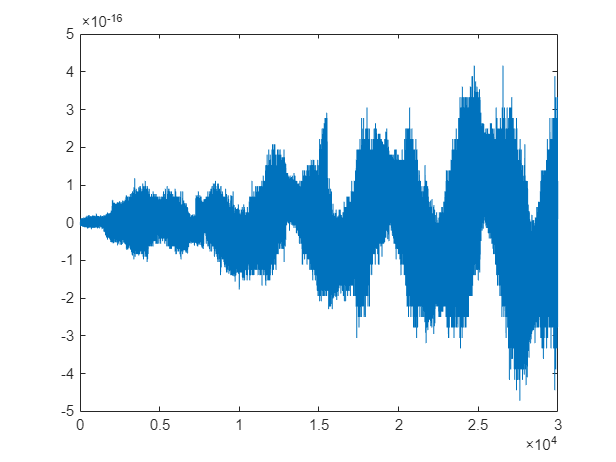

figure; plot(t, ydotJ3B - y_dot)

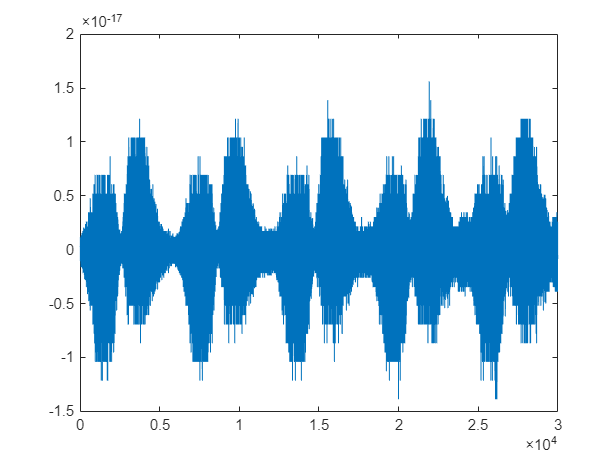

figure; plot(t, zdotJ3B - z_dot)